# Simple script to generate DLV model data

clear;clc;

% Parameter setup and model invocation

param.N_neur = 256; % Number of “neurons” (binary units)
param.N_F = 4; % Number of latent fields hₘ(t)
% param.tau_F = [0.001 0.01 0.1 1]; % Time constants (in seconds) for each OU field
param.T = 120; % Total simulation time (in seconds)
param.dt = 1e-3;  
param.f_peak = [5, 10, 20, 40];
param.zeta_val = [0.1, 0.1, 0.1, 0.1];

% param.fixJ_if = randn(param.N_neur, param.N_F)/sqrt(param.N_F); % ordered_J_if; %
% param.eta_val = 1;
% param.eps_val = 6.91; % 1 or 2.67 *param.eta_val previous, "Inverse temperature" and silence bias
[s_i, param, h_f] = sampleMorrellModel(param);

% % parameters you already have
% dt = param.dt;            % 1e-4
% desired_rate = 20;         % Hz, change this to 1, 2, 10 etc.
% p_target = desired_rate * dt;        % per-bin spike probability
% z_target = log(p_target ./ (1 - p_target));  % desired logistic argument (~-7..-12)
% 
% % estimate mean input from J_if and h_f (use processed/steady-state h_f)
% % h_f is Time x N_F
% mean_h = mean(h_f, 1)';   % N_F x 1  (column vector)
% mean_input_per_neuron = param.fixJ_if * mean_h;  % N_neur x 1
% mean_input = mean(mean_input_per_neuron);       % scalar average input across neurons
% 
% % choose eta (gain); try a reasonable starting point
% eta_try = param.eta_val;   % try 0.1, 0.5, 1.0, 2.0 depending on how sensitive your system is
% 
% % recommended eps to get mean z = z_target:
% eps_recommend = eta_try * mean_input - z_target;
% 
% fprintf('mean_input=%.3g, eta=%.3g -> recommend eps ≈ %.3g for target rate %.2f Hz\n',...
%         mean_input, eta_try, eps_recommend, desired_rate);

% param.eps_val = eps_recommend;
% param.eps_val = 6.91;
% [s_i, param, h_f] = sampleMorrellModel(param);
% % After running sampleMorrellModel
% % s_i is N_neur x T binary matrix
% mean_per_neuron = mean(s_i, 2);      % per-neuron average per bin
% firing_rates_Hz = mean_per_neuron / param.dt;  % Hz
% fprintf('Population mean rate = %.3f Hz (median %.3f Hz)\n',...
%     mean(firing_rates_Hz), median(firing_rates_Hz));


% Marchenko–Pastur threshold
eig_vals = eig(cov(s_i'));
[N, T] = size(s_i);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 37 PCs


## **Visualizing the Raw data and the latent variables**

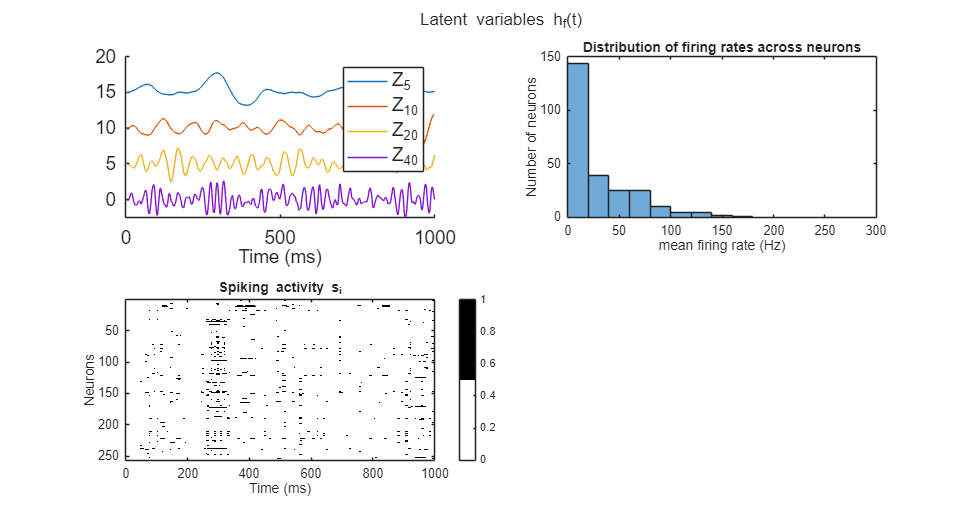

% s_centered = double(s_i) - mean(s_i,2);
mean_rate_Hz = mean(s_i,2) / param.dt;
fs_orig = 1/param.dt;
fs_new  = 512;  
time_ms = (0:T-1) * param.dt * 1000; % time in milliseconds
map = [1 1 1 
    0 0 0];
figure('Position',[50 50 1500 800])
tiledlayout(2,2)
% Latent variables
nexttile
% plot(time_ms, h_f)
% xlabel('Time (ms)')
% ylabel('Latent field amplitude')
% xlim([0 1000]);   % show first 500 ms
% title('Latent variables h_f(t)')
% legend(sprintf('Z_{%0.3f}', param.tau_F(1)),...
%     sprintf('Z_{%0.3f}', param.tau_F(2)),...
%     sprintf('Z_{%0.3f}', param.tau_F(3)),...
%     sprintf('Z_{%0.3f}', param.tau_F(4)));  
h_f_colors = lines(param.N_F);
% y_limits = [-4 4];  % force consistent y-scale
offset = 5;
time_hf_ds = time_ms * fs_new/fs_orig;

hold on
for f = 1:param.N_F
    % nexttile
    plot(time_ms,h_f(:, f)+(param.N_F-f)*offset, 'Color', h_f_colors(f,:));
    xlim([0 1000]);
  
end
xlabel('Time (ms)');
legend(sprintf('Z_{%d}', param.f_peak(1)),...
    sprintf('Z_{%d}', param.f_peak(2)),...
    sprintf('Z_{%d}', param.f_peak(3)),...
    sprintf('Z_{%d}', param.f_peak(4)));  
hold off


sgtitle('Latent variables h_f(t)'); % overall title
set(findall(gcf,'-property','FontSize'),'FontSize',14);
nexttile
histogram(mean_rate_Hz);
xlim([0 300]);
% set(gca, 'YScale', 'log'); 
xlabel('mean firing rate (Hz)');
ylabel('Number of neurons');
title('Distribution of firing rates across neurons');

% Spiking activity
nexttile
imagesc(time_ms, 1:param.N_neur, s_i)
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i')
colormap(map); 
colorbar;

## looking at PCA and relationship to ground truth (h_f, J_if)

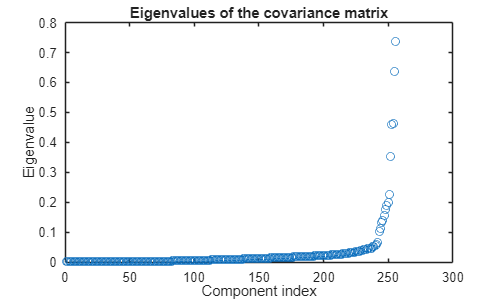

% getting the eigenvalues of covariance matrix
eig_vals = eig(cov(s_i'));
figure('Position',[100 100 500 300]) 
plot(eig_vals, 'o')
xlabel('Component index')
ylabel('Eigenvalue')
title('Eigenvalues of the covariance matrix')

warning('off', 'MATLAB:rankDeficientMatrix')
s_i_double = double(s_i);

% Skipping the first half second transient
half_a_sec = 0.5/param.dt;
s_i_double_pt = s_i_double(:,half_a_sec:end);
h_f_pt = h_f(half_a_sec:end,:);
time_ms_pt = time_ms(half_a_sec:end)-500;


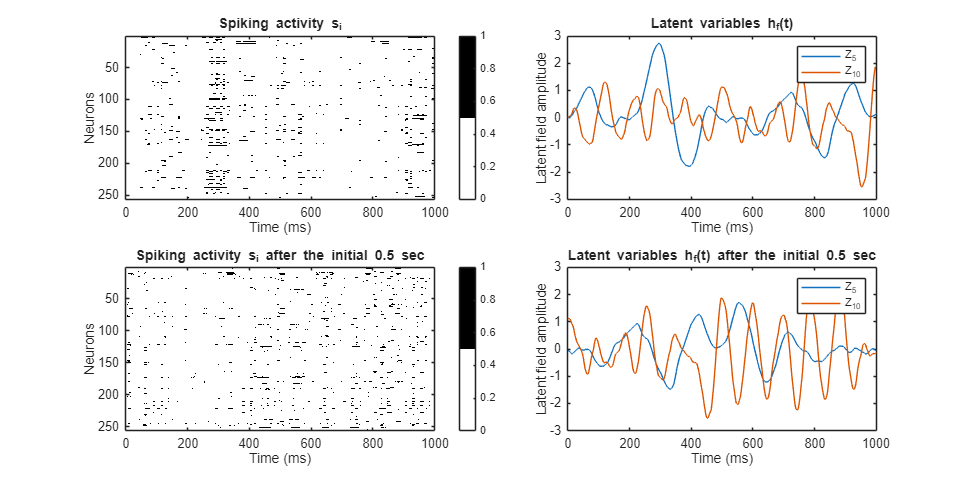

figure('Position',[50 50 1200 600])
tiledlayout(2,2)
% Spiking activity
nexttile
imagesc(time_ms, 1:param.N_neur, s_i)
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i')
colormap(map); 
colorbar;

% Latent variables
nexttile
plot(time_ms, h_f(:,1:2))
xlabel('Time (ms)')
ylabel('Latent field amplitude')
xlim([0 1000]);   % show first 500 ms
title('Latent variables h_f(t)')
legend(sprintf('Z_{%d}', param.f_peak(1)), sprintf('Z_{%d}', param.f_peak(2)));

% Spiking activity after 0.5 sec
nexttile
imagesc(time_ms_pt(1:2*half_a_sec+1), 1:param.N_neur, s_i_double_pt(:, 1:2*half_a_sec+1))
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i after the initial 0.5 sec')
colormap(map); 
colorbar;

% Latent variables after 0.5 sec
nexttile
plot(time_ms_pt(1:2*half_a_sec+1), h_f_pt(1:2*half_a_sec+1,1:2));
xlabel('Time (ms)')
ylabel('Latent field amplitude')
xlim([0 1000]);   % show first 500 ms
title('Latent variables h_f(t) after the initial 0.5 sec')
legend(sprintf('Z_{%d}', param.f_peak(1)), sprintf('Z_{%d}', param.f_peak(2)));

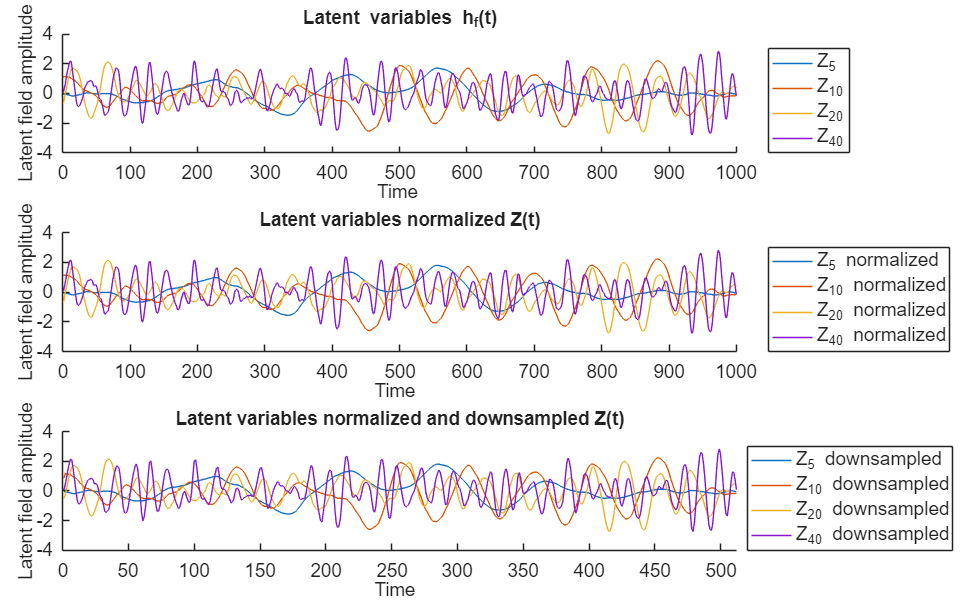

% --- 2) Resample latent fields (time x N_F) ---
[T_hf, N_F] = size(h_f_pt);
fs_orig = 1/param.dt;
fs_new  = 512;   
h_f_ds = zeros(ceil(T_hf * fs_new / fs_orig), N_F);
for fidx = 1:N_F
    yhf = resample(double(h_f_pt(:, fidx)), fs_new, fs_orig); % col vector
    h_f_ds(1:length(yhf), fidx) = yhf;
end
h_f_ds = h_f_ds(1:length(yhf), :);  % enforce exact truncation (all columns same length)

% Normalize latent variables by their variance (per column)

h_f_normalized = h_f_pt ./ std(h_f_pt, 0, 1);  % Time × N_F
h_f_normalized_ds = h_f_ds ./ std(h_f_ds, 0, 1);  % Time × N_F

figure('Position',[50 50 1200 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_pt(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d}', param.f_peak(f))]);
end
xlabel('Time ')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
ylim([-4 4]);
legend( 'Show', 'Location', 'southeastoutside');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_normalized(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d} normalized', param.f_peak(f))]);
end
xlabel('Time  ')
ylabel('Latent field amplitude')
title('Latent variables normalized Z(t)')
xlim([0 1000]);
ylim([-4 4]);
legend( 'Show','Location', 'southeastoutside');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_normalized_ds(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d} downsampled', param.f_peak(f))]);
end
xlabel('Time  ')
ylabel('Latent field amplitude')
title('Latent variables normalized and downsampled Z(t)')
xlim([0 1000*fs_new/fs_orig]);
ylim([-4 4]);
legend( 'Show','Location', 'southeastoutside');
hold off;

set(findall(gcf,'-property','FontSize'),'FontSize',14);

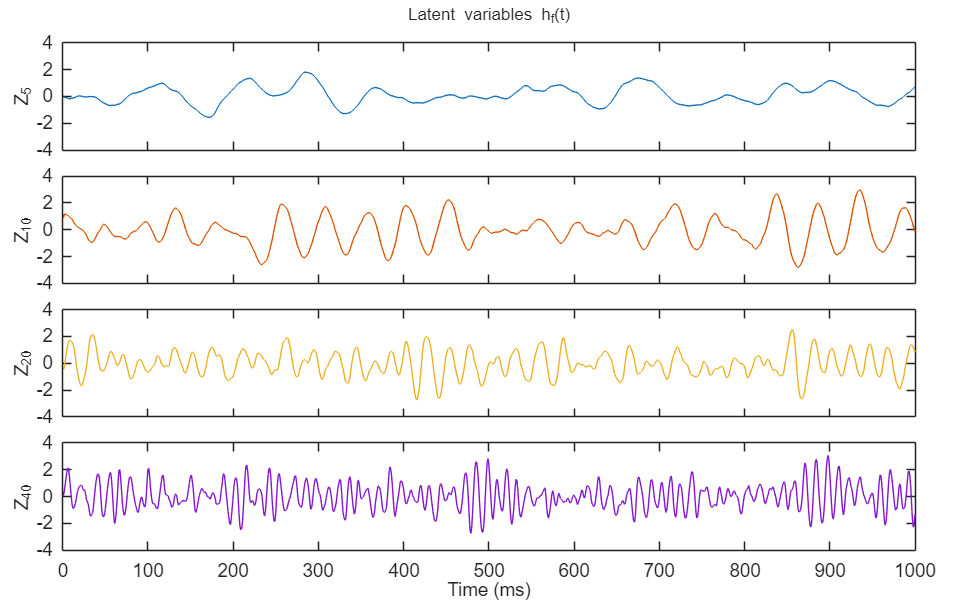

figure('Position',[50 50 1200 750])
tiledlayout(param.N_F, 1, 'TileSpacing','compact','Padding','compact');

h_f_colors = lines(param.N_F);
y_limits = [-4 4];  % force consistent y-scale

for f = 1:param.N_F
    nexttile
    plot(h_f_normalized_ds(:, f), 'Color', h_f_colors(f,:));
    xlim([0 1000]);
    ylim(y_limits);
    ylabel(sprintf('Z_{%d}', param.f_peak(f)));
    if f < param.N_F
        set(gca, 'XTickLabel', []); % hide x labels for middle plots
    else
        xlabel('Time (ms)');
    end
end

sgtitle('Latent variables h_f(t)'); % overall title
set(findall(gcf,'-property','FontSize'),'FontSize',14);

## Spike to EEG like signal

% % 1. Temporal binning
% original_bin_size = param.dt; % original bin size 0.01 sec (10 ms)
% target_bin_size = 0.01; % bin into 10 msec intervals
% bin_ratio = target_bin_size / original_bin_size;
% 
% % Downsample by summing over non-overlapping bins
% [N, T] = size(s_i);
% T_new = floor(T / bin_ratio);
% s_binned = zeros(N, T_new);
% 
% for t = 1:T_new
%     idx_start = (t-1)*bin_ratio + 1;
%     idx_end = t*bin_ratio;
%     s_binned(:, t) = sum(s_i(:, idx_start:idx_end), 2);
% end
% 
% figure()
% nexttile
% imagesc(time_ms, 1:param.N_neur,s_binned)
% xlim([0 500]);   % show first 500 ms
% xlabel('Time (ms)')
% ylabel('Neurons')
% title(['Spiking activity s binned into ', num2str(target_bin_size), ' sec bins'])
% colormap('jet');  % or 'parula', 'turbo', etc.
% colorbar;

% 2. Add inhibitory neurons
% ------------------------
if ~isfield(param, 'inhib_frac')
    param.inhib_frac = 0.2;  % default 20% inhibitory
end

nInhib = round(param.inhib_frac * N);
inhib_idx = randperm(N, nInhib);
s_i_double_pt_inhib = s_i_double_pt;
s_i_double_pt_inhib(inhib_idx, :) = -s_i_double_pt(inhib_idx, :);  % inhibitory neurons as negative

% Display inhibitory neurons:
fprintf("Inhibitory Neuron indecies are: %s", num2str(sort(inhib_idx)));

Inhibitory Neuron indecies are: 1    7   22   27   29   33   37   43   51   55   56   70   78   89   97   98  105  111  128  133  138  139  140  141  144  150  152  159  169  171  173  177  184  192  193  195  199  208  210  214  215  218  226  230  232  239  241  243  252  254  256

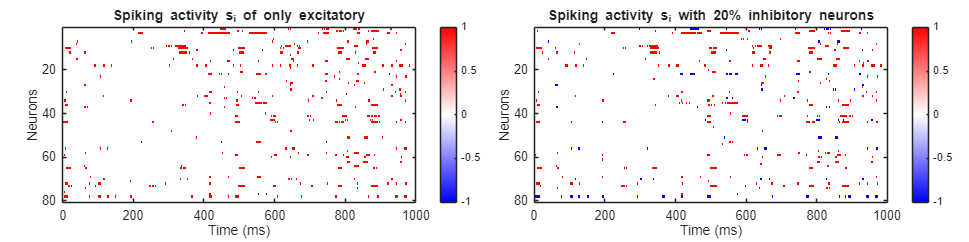


neurons_to_plot = 10*8; % 10 channels, 8 neuron per channel for EEG

% Custom red-white-blue colormap
n = 256;
rwb = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1);    % blue→white
       ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];   % white→red


figure('Position',[50 50 1200 300])
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
imagesc(time_ms_pt(1:2*half_a_sec+1), 1:neurons_to_plot, s_i_double_pt(1:neurons_to_plot, 1:2*half_a_sec+1))
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i of only excitatory')
colormap(rwb); 
colorbar;
clim([-1 1]);

nexttile
imagesc(time_ms_pt(1:2*half_a_sec+1), 1:neurons_to_plot, s_i_double_pt_inhib(1:neurons_to_plot, 1:2*half_a_sec+1))
xlabel('Time (ms)')
ylabel('Neurons')
xlim([0 1000]);   % show first 500 ms
title('Spiking activity s_i with 20% inhibitory neurons')
colormap(rwb); 
colorbar;
clim([-1 1]);

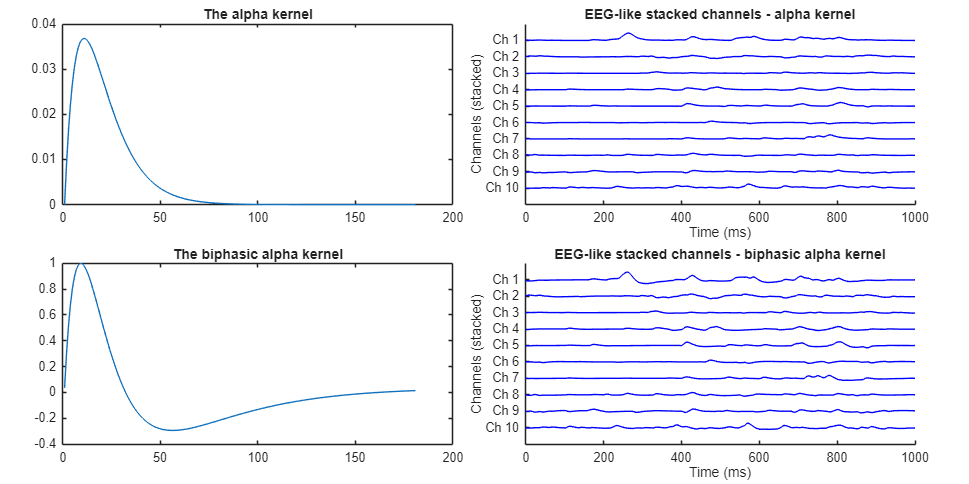

% 2. Convolving with post-synaptic kernel: choosing the Alpha kernel that
% models realistic synaptic current with rise and fall
% Alpha kernel: rise-then-decay shape
tau_pos = 0.01;       % alpha time constant for positive lobe (seconds), e.g. 10 ms
tau_neg = 0.03;       % time constant for negative lobe, e.g. 30 ms
tmax_factor = 6;      % how many taus to include (8 is safe)
dt_kernel = param.dt; % kernel sampling step (use same as sim or coarser)

% --- Build common time vector (seconds) ---
tmax = tmax_factor * max(tau_pos, tau_neg);
t = 0:dt_kernel:tmax;  % same t for all kernels

% --- Alpha kernel (canonical) ---
alpha_k = (t ./ tau_pos) .* exp(-t ./ tau_pos);
alpha_k = alpha_k / sum(alpha_k);   % normalize by area (or use max)

% Apply alpha kernel convolution per neuron
group_size = 8;
num_channels = floor(N / group_size);
T_new = size(s_i_double_pt_inhib,2);
s_convolved_alpha = zeros(num_channels, T_new ); % output length after conv, + length(alpha_kernel) - 1

for ch = 1:num_channels
    % Neuron indices for this group
    idx_start = (ch - 1)*group_size + 1;
    idx_end = ch * group_size;

    % Sum of convolved signals in this group
    signal = zeros(1, T_new ); %+ length(alpha_kernel) - 1
    for i = idx_start:idx_end
        spk = s_i_double_pt_inhib(i, :);
        % Choose kernel: alpha_kernel or exp_kernel
        conv_spk = conv(spk, alpha_k, 'same');  % or 'same' to match length
        signal = signal + conv_spk;
    end

    % Store channel
    s_convolved_alpha(ch, :) = signal;
end



% --- Biphasic kernel (two-EXP difference approach, phys-like) ---
% positive lobe (fast) and negative lobe (slower, scaled)
biphasic_k = (t ./ tau_pos).*exp(-t./tau_pos) - 0.4*(t ./ tau_neg).*exp(-t./tau_neg);
% center/sink to zero mean if you want
biphasic_k = biphasic_k - mean(biphasic_k);
% normalize by peak absolute value (optional, to compare shapes)
biphasic_k = biphasic_k / max(abs(biphasic_k));


% 4. Group Neurons + Convolution
% ------------------------
num_channels = floor(N / group_size);
num_channels_plot = 10;
s_convolved = zeros(num_channels, T_new);

for ch = 1:num_channels
    idx = (ch - 1)*group_size + (1:group_size);
    conv_sum = zeros(1, T_new);
    for i = idx
        conv_sum = conv_sum + conv(s_i_double_pt_inhib(i, :), biphasic_k, 'same');
    end
    s_convolved(ch, :) = conv_sum;
end

figure('Position',[50 50 1200 600])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile
plot(1:length(alpha_k), alpha_k);
title("The alpha kernel");

nexttile;
offset = 5; % vertical spacing between channels
hold on

for ch = 1:num_channels_plot
    % plot each channel stacked upward
    plot(time_ms_pt, s_convolved_alpha(ch+1,:) + (num_channels_plot - ch)*offset, 'b');
end
hold off

xlim([0 1000]);
ylim([-offset, num_channels_plot*offset]);

xlabel('Time (ms)');
ylabel('Channels (stacked)');
yticks((0:num_channels_plot-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels_plot - c + 1), 1:num_channels_plot, 'UniformOutput', false));
title('EEG-like stacked channels - alpha kernel');

nexttile
plot(1:length(biphasic_k), biphasic_k);
title("The biphasic alpha kernel");
% imagesc(time_ms_pt, 1:num_channels,s_convolved)
% xlabel('Time (ms)')
% xlim([0 100]);   % show first 500 ms
% ylabel('Channels')
% title('Spiking activity Convolved with post-synaptic kernel')
% colormap('bone'); 
% colorbar;
offset = 100; % vertical spacing between channels

nexttile;
hold on

for ch = 1:num_channels_plot
    % plot each channel stacked upward
    plot(time_ms_pt, s_convolved(ch+1,:) + (num_channels_plot - ch)*offset, 'b');
end
hold off

xlim([0 1000]);
ylim([-offset, num_channels_plot*offset]);

xlabel('Time (ms)');
ylabel('Channels (stacked)');
yticks((0:num_channels_plot-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels_plot - c + 1), 1:num_channels_plot, 'UniformOutput', false));
title('EEG-like stacked channels - biphasic alpha kernel');

% % 3. Smoothing (Gaussian) to mimic the continous nature of EEG
% % Define smoothing kernel
% smooth_sigma = 2;  % std dev of the Gaussian kernel in bins
% kernel_size = 6 * smooth_sigma;
% x = -kernel_size:kernel_size;
% gauss_kernel = exp(-x.^2 / (2 * smooth_sigma^2));
% gauss_kernel = gauss_kernel / sum(gauss_kernel);  % normalize
% 
% % Apply smoothing along time (per neuron)
% s_smoothed = zeros(size(s_convolved));
% for i = 1:num_channels
%     s_smoothed(i, :) = conv(s_convolved(i, :), gauss_kernel, 'same');
% end
% 
% figure('Position', [50 50 1500 400])
% nexttile
% imagesc(time_ms, 1:num_channels,s_smoothed)
% xlabel('Time (ms)')
% xlim([0 500]);
% ylabel('Channels')
% title('Spiking activity Smoothed Activity')
% colormap('jet');
% 
% nexttile
% contourf(s_smoothed, 20, 'LineColor', 'none');
% xlabel('Time (ms)');
% xlim([0 500]);
% ylabel('Neuron Index');
% title('Contour of Smoothed Activity');
% colormap('jet');
% colorbar;

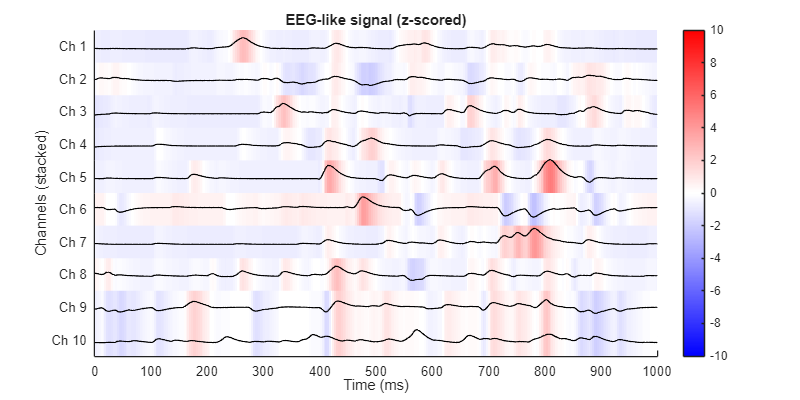

% 4. Centering and normalizing
% Z-score across time for each neuron
% Normalize (z-score) across time
% Normalize (z-score) across time
s_eeg_like = zscore(s_convolved_alpha, 0, 2);

% Custom red-white-blue colormap
n = 256;
rwb = [linspace(0,1,n/2)', linspace(0,1,n/2)', ones(n/2,1);    % blue→white
       ones(n/2,1), linspace(1,0,n/2)', linspace(1,0,n/2)'];   % white→red

num_channels = 10;
offset = 10; % vertical spacing between channels

figure('Position', [50 50 800 400])
hold on;

% Plot each channel heatmap and line
for ch = 1:num_channels
    y_center = (num_channels - ch) * offset;   % same center for heatmap & trace
    
    % Corrected heatmap vertical placement
    imagesc(time_ms_pt, ...
            [y_center - offset/2, y_center + offset/2], ...
            s_eeg_like(ch,:)); 
end

colormap(rwb);
colorbar;
clim([-10 10]);
set(gca, 'YDir', 'normal');

% Plot EEG traces on top of heatmaps
for ch = 1:num_channels
    y_center = (num_channels - ch) * offset;
    plot(time_ms_pt, s_eeg_like(ch+1,:) + y_center, 'k', 'LineWidth', 1);
end

% Adjust limits and labels
xlim([0 1000]);
ylim([-offset/2, (num_channels-0.5)*offset]);
xlabel('Time (ms)');
ylabel('Channels (stacked)');

yticks((0:num_channels-1)*offset);
yticklabels(arrayfun(@(c) sprintf('Ch %d', num_channels - c + 1), 1:num_channels, 'UniformOutput', false));

title('EEG-like signal (z-scored)');
hold off;

% testing Spike to EEG function:
% target_bin_size = 0.01; % 10 ms
% tau = 10; % Post-synaptic kernel, Alpha kernel's number of bins to the peak of the kernel
smooth_sigma = 2; % Std. Dev. of the Gaussian kernel in bins
group_size = 8; % grouping of neurons per channel
param.T = 120;

[s_eeg_like, h_f_processed] = spike_to_eeg(s_i, h_f, param, group_size, smooth_sigma);

[s_i_test, param_test, h_f_test] = sampleMorrellModel(param);
[s_eeg_like_test, h_f_processed_test] = spike_to_eeg(s_i_test,h_f_test, param, group_size, smooth_sigma);

% Marchenko–Pastur threshold
eig_vals = eig(cov(s_eeg_like'));
[N, T] = size(s_i);
Q = T / N;
sigma2 = mean(eig_vals);           % crude estimate of noise variance
lambda_max = sigma2 * (1 + sqrt(1/Q))^2;

% Find number of components above the MP threshold
num_sig_components = sum(eig_vals > lambda_max);
fprintf('Marchenko–Pastur suggests keeping %d PCs\n', num_sig_components);

Marchenko–Pastur suggests keeping 8 PCs


% ---- parameters ----
fs_orig = 1/param.dt;   % original sampling rate (e.g. 8000 Hz)
fs_new  = 512;          % target analysis sampling rate (Hz)
decimate_factor = fs_orig / fs_new;  % should be integer (16)

% --- 0) ensure h_f is double and shaped [T x N_F] ---
h_f_processed = double(h_f_processed);

% --- 1) Resample latent fields to fs_new (vectorized via loop over columns) ---
[T_orig, N_F] = size(h_f_processed);
T_est = ceil(T_orig * fs_new / fs_orig);
h_f_processed_ds = zeros(T_est, N_F);
for ff = 1:N_F
    h_f_processed_ds(:, ff) = resample(h_f_processed(:, ff), fs_new, fs_orig);   % returns column vector
end
T_ds = size(h_f_processed_ds,1);

% ---- 2) DFT Periodogram on downsampled signals (fast, single FFT per column) ----
% choose nfft reasonable (power of 2)
nfft_dft = 2^nextpow2(T_ds);
H = fft(h_f_processed_ds, nfft_dft);              % nfft x N_F
% keep only one-sided spectrum
half = floor(nfft_dft/2)+1;
freq_dft = (0:half-1)*(fs_new/nfft_dft);
H_F_dft_psd = (1/(fs_new * nfft_dft)) * abs(H(1:half,:)).^2;  % PSD: freq x N_F

% ---- 3) Welch PSD on downsampled signals (recommended) ----
% choose window and nfft relative to fs_new (e.g. 1024 samples => ~2.048 s at 500 Hz)
win_len = 2048;                    % window length in samples (tunable)
if win_len > T_ds
    win_len = 2^floor(log2(T_ds/4));   % fallback to smaller window
end
noverlap = round(win_len/2);       % 50% overlap
nfft_welch = 4096;                 % frequency resolution, tunable (>= win_len)

window = hamming(win_len);
% pwelch accepts matrix input with columns = channels (time x channels)
[H_F_welch_psd, f_welch_psd] = pwelch(h_f_processed_ds, window, noverlap, nfft_welch, fs_new);
% H_F_welch_psd is nFreq x N_F

% ---- 4) Optional: quick checks / plotting ----
fprintf('Original T = %d samples -> downsampled T_ds = %d samples (fs=%d Hz)\n', T_orig, T_ds, fs_new);

Original T = 119501 samples -> downsampled T_ds = 61185 samples (fs=512 Hz)


fprintf('Welch: window=%d, overlap=%d, nfft=%d, nFreq=%d\n', win_len, noverlap, nfft_welch, size(H_F_welch_psd,1));

Welch: window=2048, overlap=1024, nfft=4096, nFreq=2049


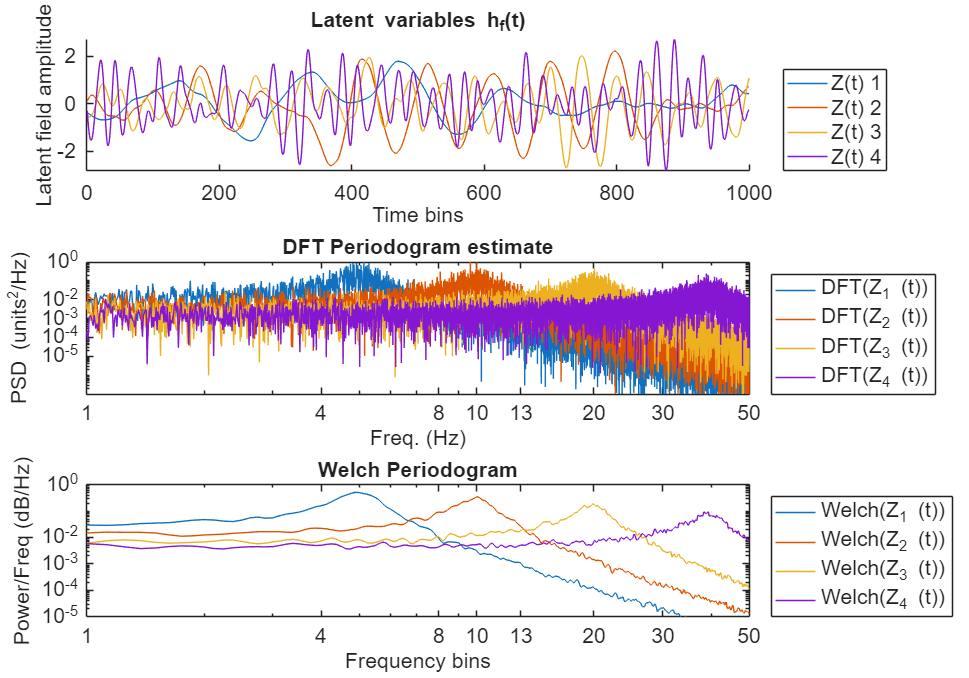

figure('Position',[50 50 1000 700])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_processed(:, f), 'Color', h_f_colors(f, :),'DisplayName', ['Z(t) ' num2str(f)]);
end
xlabel('Time bins')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
legend( 'Show', 'Location','southeastoutside');
hold off;

nexttile
for f=1:param.N_F
    loglog(freq_dft, H_F_dft_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['DFT(Z_{' num2str(f) '} (t))']);
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
ylim([1e-7, 1]);
yticks([0.00001, 0.0001, 0.001, 0.01, 1]);
xlabel('Freq. (Hz)'); ylabel('PSD (units^2/Hz)');
title('DFT Periodogram estimate');
legend('show', 'Location','southeastoutside');
xlim([1, 50]);
hold off;

nexttile
for f=1:param.N_F
    loglog(f_welch_psd, H_F_welch_psd(:,f),'Color',h_f_colors(f,:),'DisplayName',['Welch(Z_{' num2str(f) '} (t))']); % 
    hold on;
end
xticks([1, 4, 8, 10, 13, 20, 30, 50]) 
yticks([0.003, 0.005, 0.01, 0.02]);
ylim([0.00001, 1]);
yticks([0.00001, 0.0001, 0.001, 0.01, 1]);
xlabel('Frequency bins')
ylabel('Power/Freq (dB/Hz)')
title('Welch Periodogram')
legend('show', 'Location','southeastoutside');
xlim([1, 50]);
hold off;
set(findall(gcf,'-property','FontSize'),'FontSize',16);

[COEFF, SCORE, LATENT, TSQUARED, EXPLAINED, MU] = pca(double(s_i'));

% Find how many PCs are needed to explain 85% variance
cum_explained = cumsum(EXPLAINED);
num_pcs_85percent = find(cum_explained >= 85, 1, 'first');
num_comp = num_pcs_85percent +20;
num_com_to_plot = 10;
time_points = linspace(1,param.T,1000);

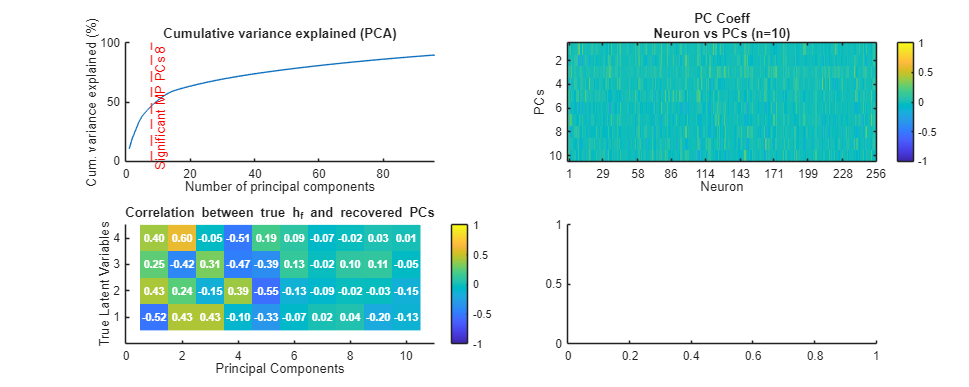

figure('Position', [100 100 2000 800]) 
nexttile
hold on;
plot(cum_explained)
xlim([0 num_comp]);
ylim([0 100]);
xline(num_sig_components,'--r', ['Significant MP PCs ' num2str(num_sig_components)]);
xlabel('Number of principal components')
ylabel('Cum. variance explained (%)')
title('Cumulative variance explained (PCA)')

nexttile
imagesc(COEFF(:,1:num_com_to_plot)', [-1 1]);
title({'PC Coeff'; ['Neuron vs PCs (n=' num2str(num_com_to_plot) ')']});
xlabel('Neuron'); ylabel('PCs'); colorbar;
xlim([0 size(COEFF,1)]);
num_t_ticks = 10;
t_tick_idx = round(linspace(1, size(COEFF,1), num_t_ticks));
t_tick_lbl = arrayfun(@(x) sprintf('%d', x), t_tick_idx, 'UniformOutput', false);
set(gca, 'XTick', t_tick_idx, 'XTickLabel', t_tick_lbl);

nexttile
% Correlation between latent fields and PCA activations
cc_mat = corrcoef([h_f(1:size(SCORE,1),:) SCORE(:, 1:num_com_to_plot)]);
cc_mat_sub = cc_mat(1:4, 5:end);
hold on;
imagesc(cc_mat_sub, [-1 1]); colorbar;
yticks(1:4);
xlim([0 num_com_to_plot+1]);
title('Correlation between true h_f and recovered PCs');
xlabel('Principal Components');
ylabel('True Latent Variables');
% Add numerical annotations
for i = 1:size(cc_mat_sub,1)
    for j = 1:size(cc_mat_sub,2)
        text(j, i, sprintf('%.2f', cc_mat_sub(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'w', 'FontSize',8, ...
            'FontWeight', 'bold');
    end
end
hold off;

nexttile

[~, ord1] =sort(param.fixJ_if(:, 1)); % Sorting the neurons by their true coupling to latent 1

Unrecognized field name "fixJ_if".

% Showing side-by-side the true J_i,m versus the first 10 PCA oadings
% rescaled 
imagesc([param.fixJ_if(ord1, :) COEFF(ord1, 1:num_com_to_plot)*sqrt(num_channels/param.N_F)], [-1 1])
xlabel('Latent dim or PC index')
ylabel('Neuron idx (sorted by loading on J_{i1})')
title({['loadings (J_{if}) on latent variables (rows 1 -' num2str(param.N_F) ')']; ... 
    ' and PCA activations'}, 'interpreter', 'tex')
colorbar

% nexttile
% imagesc(cc_mat, [-1 1])
% xlabel('PCA components')
% ylabel('Latent variable index')
% title(['corr btw latent variables (rows 1-' num2str(param.N_F) ') and PCA activations'])
% colorbar

## Reconstruction Error vs. PC number

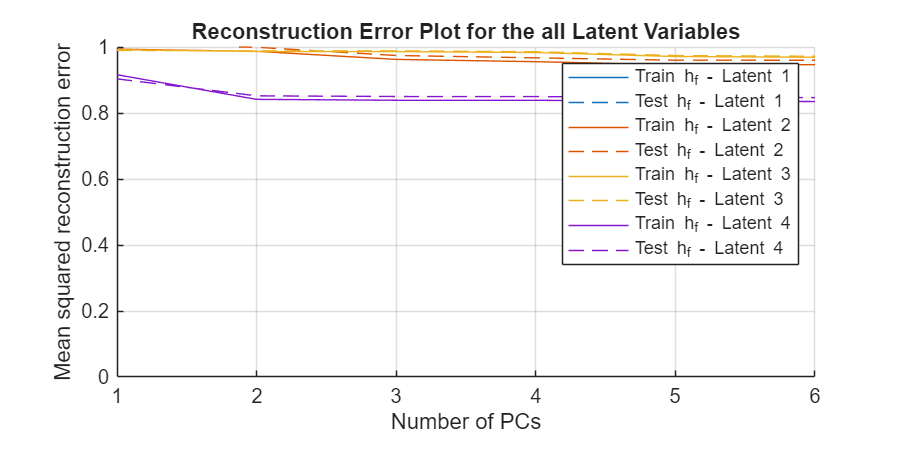

reconstruction_error = zeros(num_sig_components,param.N_F);
reconstruction_error_test = zeros(num_sig_components,param.N_F);

s_i_test_double = double(s_i_test);
SCORE_test = s_i_test_double' * COEFF; 

for idx = 1:num_sig_components
    err_train = 0;
    err_test = 0;
    for f = 1:param.N_F % calculating the Recon. Error for all 4 latents
        % Expressing each latent field as a linear combinatino of PCA time
        % course with least-square method
        x_train = lsqlin(SCORE(:, 1:idx), h_f(:,f));
        h_f_reconstructed = SCORE(:, 1:idx) * x_train;
        reconstruction_error(idx,f) = mean((h_f(:,f) - h_f_reconstructed).^2);

        h_f_test_reconstructed = SCORE_test(:, 1:idx) * x_train;
        reconstruction_error_test(idx,f) = mean((h_f_test(:,f) - h_f_test_reconstructed).^2);
    end
     
end

figure(Position=[100,100, 600, 300])
nexttile
hold on;
h_f_colors = lines(param.N_F);

for f = 1:param.N_F
    plot(1:num_sig_components, reconstruction_error(:, f), 'Color',h_f_colors(f,:),'DisplayName', ['Train h_f - Latent ' num2str(f)]);
    plot(1:num_sig_components, reconstruction_error_test(:, f), 'LineStyle', '--', 'Color',h_f_colors(f,:),'DisplayName', ['Test h_f - Latent ' num2str(f)]);
end
xlim([1 num_sig_components]);
ylim([0 1]);
xlabel('Number of PCs');
ylabel('Mean squared reconstruction error');
legend('show');
title('Reconstruction Error Plot for the all Latent Variables');
grid on;
hold off;

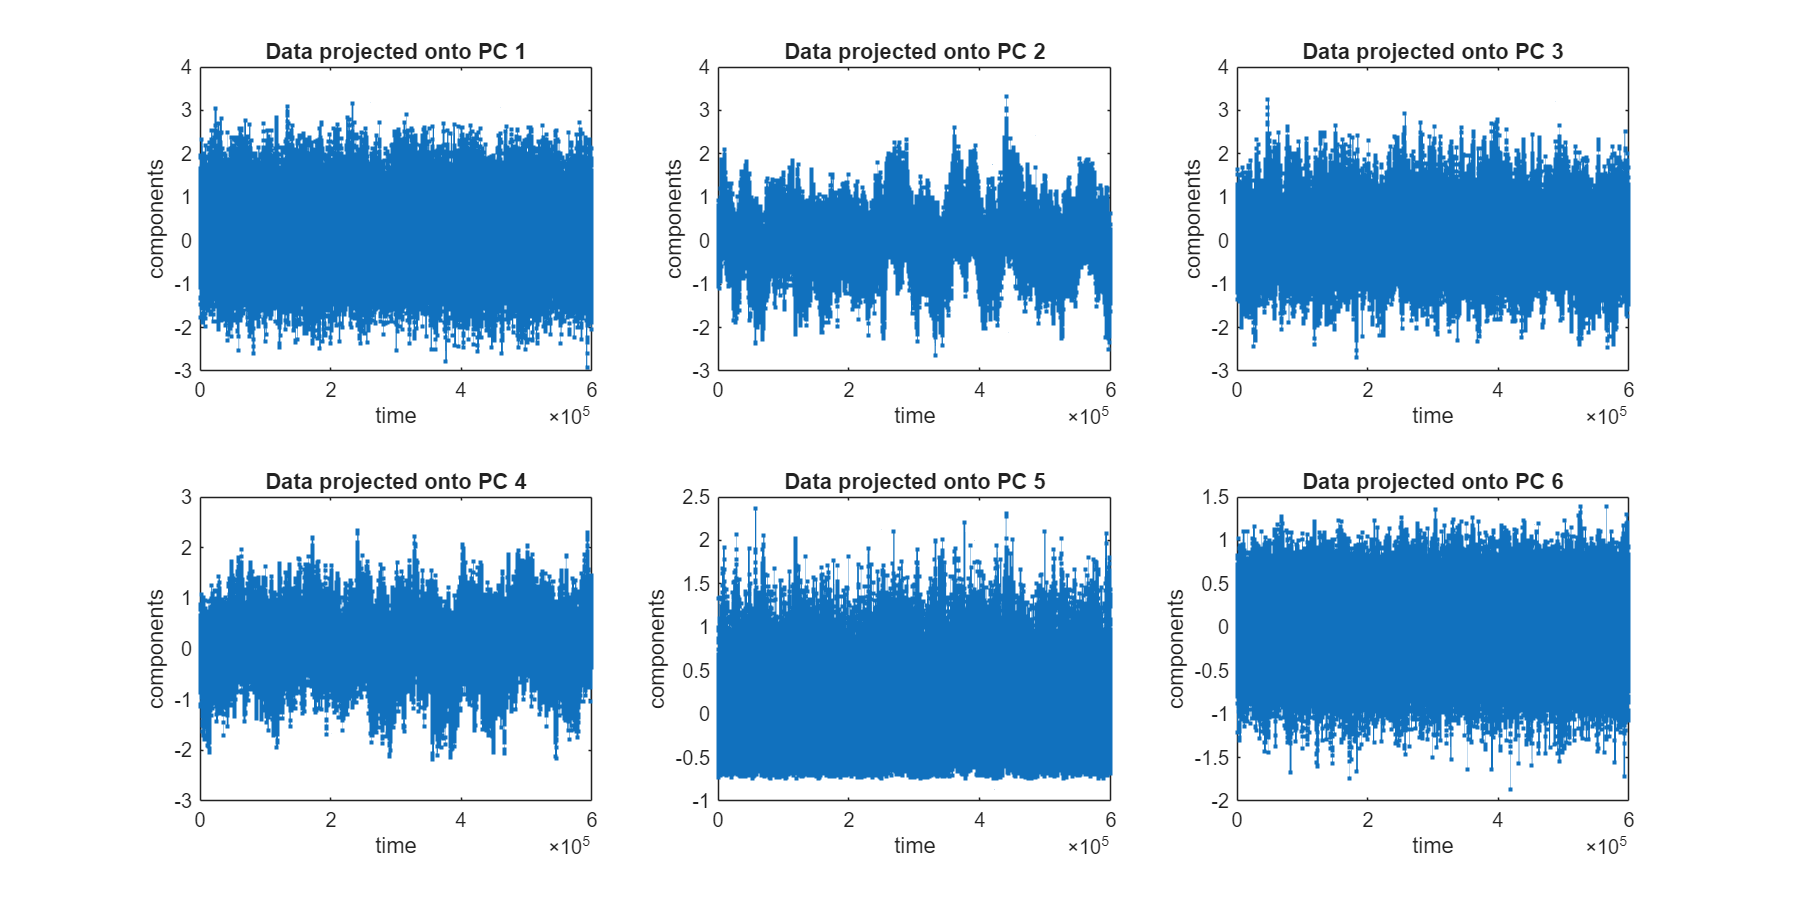


figure(Position=[100,100, 1200, 600])
tiledlayout(ceil(num_sig_components/2), 2); % adjust grid size as needed

for i=1:num_sig_components
    hold on
    nexttile;
    plot(1:size(SCORE,1), SCORE(:, i), '.-', 'linewidth', 1) %,'Color',pc_colors(i,:)
    title(['Data projected onto PC ',num2str(i)])
    ylabel('components')
    xlabel('time')
    
end

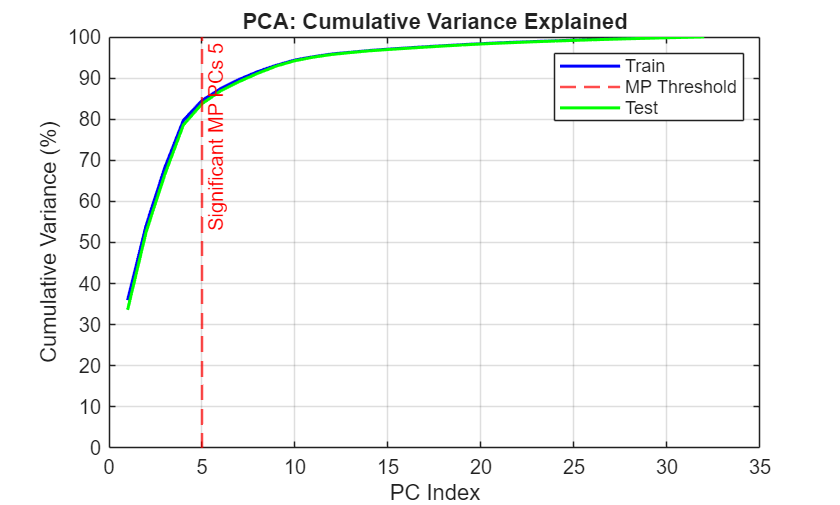

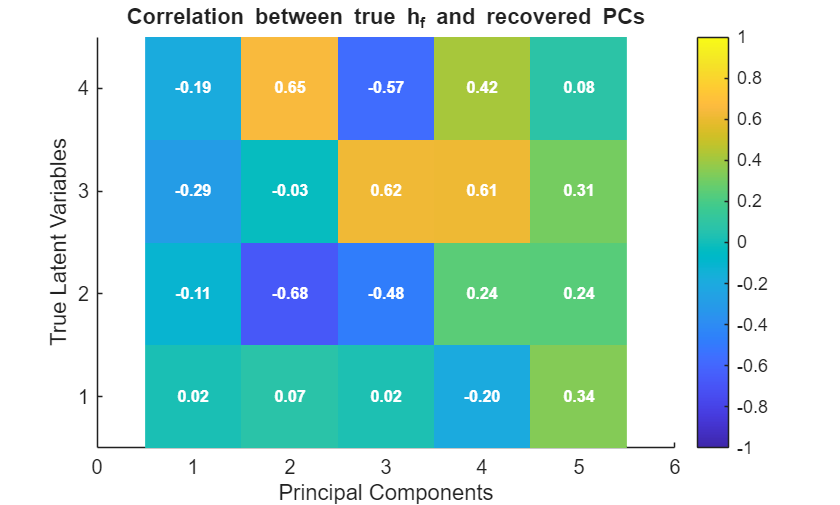

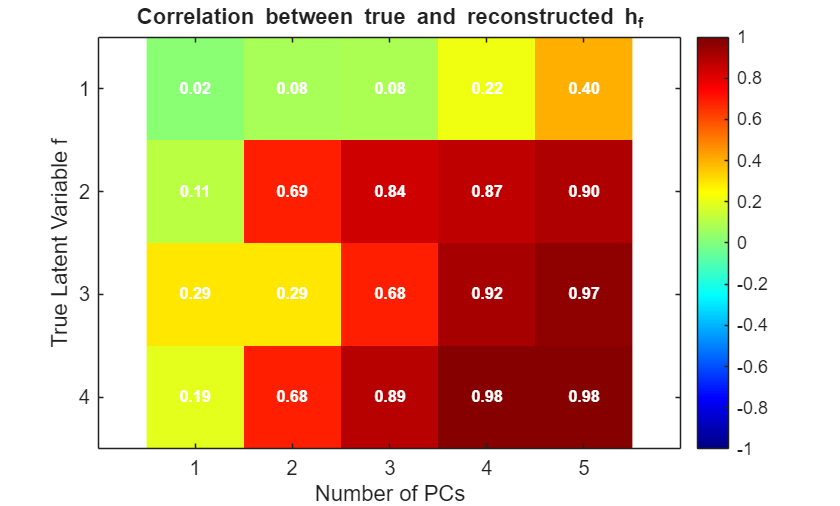

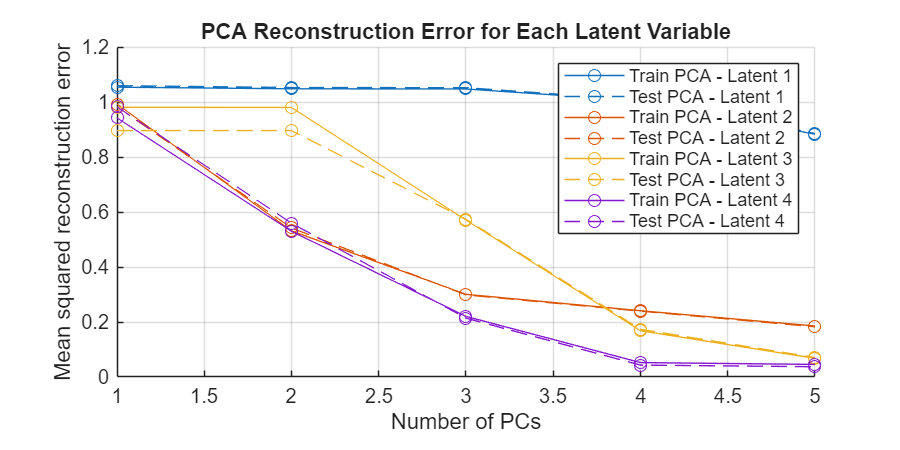

% Run PCA function for EEG-like signal:

[coeff, score, explained, reconstruction_error_pca, reconstruction_error_test_pca] = ...
    runPCAAnalysis(s_eeg_like, s_eeg_like_test, h_f_processed, h_f_processed_test, param, num_sig_components);

## Simulate a "readout" of the population activity and look at the power spectrum

% neuron_locations = 1:param.N_neur;
% center_loc = 128;
% nbhd_width = 32;
% w_readout = exp(- (neuron_locations - center_loc).^2/(2*nbhd_width));
% 
% local_readout = w_readout*s_i;
% 
% figure()
% nexttile
% plot(local_readout)
% xlabel('Time bins')
% ylabel('Local readout signal')
% title('Population readout from Gaussian-weighted subset')
% 
% [psd, f_psd] = pwelch(local_readout);
% nexttile
% plot(log10(f_psd), log10(psd))
% xlabel('log_{10} Frequency (Hz)')
% ylabel('log_{10} Power spectral density')
% title('Log–log power spectrum of local readout')

## ICA Test

% PCA assumes uncorrelated Gaussian mixtures, but my latent fields are
% non-Gaussian OU processes. 

% let's assume each neuron is a channel
EEG_data = s_i_double; % ch x time

% 2. Manually build a minimal EEG structure
EEG = eeg_emptyset();
EEG.data   = EEG_data;
EEG.nbchan = size(EEG.data, 1);   % number of "channels" = neurons
EEG.pnts   = size(EEG.data, 2);   % number of time points
EEG.trials = 1;                   % continuous data
EEG.srate  = 100;                 % arbitrary sample rate (adjust if needed)
EEG.xmin   = 0;
EEG = eeg_checkset(EEG);

% Run ICA without PCA
EEG = pop_runica(EEG, 'extended', 1, 'interrupt', 'off');

% The ICA activations (component time courses)
icasig = EEG.icaact;      % time course of each component, size: components × time
icasig = real(icasig);

A = EEG.icawinv;          % unmixing matrix: channels × components
W = EEG.icaweights;       % weights (unmixing) matrix

R = corrcoef([h_f, icasig']);
R_sub = R(1:4, 5:14);

figure()
hold on;
imagesc(R_sub, [-1 1]); 
colorbar;
yticks(1:4);
xlim([0 11]);
title('Correlation between true h_f and recovered ICs');
xlabel('Independent Components');
ylabel('True Latent Variables');
% Add numerical annotations
for i = 1:size(R_sub,1)
    for j = 1:size(R_sub,2)
        text(j, i, sprintf('%.2f', R_sub(i,j)), ...
            'HorizontalAlignment', 'center', ...
            'Color', 'w', ...
            'FontWeight', 'bold');
    end
end
hold off;

## Reconstruction Error

% Project test data into ICA space

% icasig_test = EEG.icawinv' * s_i_test_double;  % size: (Neuron x IC) * Neuron X time = components × time
% ICA projection of test data into IC space
icasig_test = EEG.icaweights * EEG.icasphere * s_i_test_double;

% Transpose to match h_f time dimension
icasig = double(EEG.icaact)';        % now time × components
icasig_test = double(icasig_test)';  % now time × components

reconstruction_error_ica = zeros(num_sig_components, param.N_F);
reconstruction_error_test_ica = zeros(num_sig_components, param.N_F);

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' ICs using least-squares
        x_train = lsqlin(icasig(:,1:idx), h_f(:,f));
        h_f_reconstructed_ica = icasig(:,1:idx) * x_train;
        reconstruction_error_ica(idx,f) = mean((h_f(:,f) - h_f_reconstructed_ica).^2);

        h_f_test_reconstructed_ica = icasig_test(:,1:idx) * x_train;
        reconstruction_error_test_ica(idx,f) = mean((h_f_test(:,f) - h_f_test_reconstructed_ica).^2);
    end
end

figure('Position',[100,100, 600, 300])
nexttile
hold on;
ica_colors = lines(param.N_F);

for f = 1:param.N_F
    plot(1:num_sig_components, reconstruction_error_ica(:, f), ...
        'Color', ica_colors(f,:), 'DisplayName', ['Train ICA - Latent ' num2str(f)]);
    plot(1:num_sig_components, reconstruction_error_test_ica(:, f), ...
        'LineStyle', '--', 'Color', ica_colors(f,:), 'DisplayName', ['Test ICA - Latent ' num2str(f)]);
end

xlim([1 num_sig_components]);
% ylim([0 1.4]);
xlabel('Number of ICA components');
ylabel('Mean squared reconstruction error');
legend('show');
title('ICA Reconstruction Error for Each Latent Variable');
grid on;
hold off;

% Run ICA for EEG like signal

[icasig, rec_err] = runICAAnalysis(s_eeg_like, s_eeg_like_test, h_f_processed, h_f_processed_test, param, num_sig_components);


## UMAP Test: Uniform Manifold Approximation and Projection

% Run UMAP
% 1.0: Testing different number of neighbors and min distances to consider

% n_neighbors_values = [15];
% min_dist_values = [0.1]; 
n_neighbors_values = [5, 10, 15, 30, 50, 100];
min_dist_values     = [0.1, 0.25, 0.5, 0.75];

figure('Position',[100,100, 1200, 800]);
tiledlayout(length(n_neighbors_values), length(min_dist_values), 'TileSpacing', 'compact');
warning('off', 'MATLAB:HandleGraphics:ObsoletedProperty:JavaFrame');

cluster_idx = kmeans(h_f_processed , 4);

plot_idx = 1;
for curr_n_neighbors = n_neighbors_values
    for curr_min_dist = min_dist_values
        [umap_s_i, umap_params] = run_umap(s_eeg_like', 'n_neighbors', curr_n_neighbors,...
            'min_dist', curr_min_dist,'n_components', num_sig_components, 'verbose', 'none', 'gui', false);

        nexttile(plot_idx)
        % scatter(umap_s_i(:,1), umap_s_i(:,2), 5, 'filled');
        gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
        title({['n=' num2str(curr_n_neighbors)], ['minDist=' num2str(curr_min_dist)]});
        axis tight; axis off;
        plot_idx = plot_idx + 1;
    end
end


n_components = num_sig_components;
cluster_idx = kmeans(h_f_processed , 4);
[umap_s_i, umap_params] = run_umap(s_eeg_like', 'n_neighbors', 15,...
            'min_dist', 0.1,'n_components', n_components, 'verbose', 'none', 'gui', false);

figure('Position',[100,100, 600, 600]);
gscatter(umap_s_i(:,1), umap_s_i(:,2), cluster_idx);
xlabel('UMAP Dimension 1');
ylabel('UMAP Dimension 2');
title({['UMAP Colored by Latent Variable h_f'],['n=' num2str(15)], ['minDist=' num2str(0.1)]});
colormap turbo;    % You can use 'jet', 'parula', 'hot', etc.
colorbar;
grid on;

## UMAP Recostruction Error

% Project test data into ICA space
[umap_s_i_test, umap_params_test] = run_umap(s_eeg_like_test', 'n_neighbors', 15,...
            'min_dist', 0.1,'n_components', n_components, 'verbose', 'none', 'gui', false);

% Transpose to match h_f time dimension
umap_s_i_double = double(umap_s_i)';        % now time × components
umap_s_i_double_test = double(umap_s_i_test)';  % now time × components

reconstruction_error_umap = zeros(num_sig_components, param.N_F);
reconstruction_error_test_umap = zeros(num_sig_components, param.N_F);

for idx = 1:num_sig_components
    for f = 1:param.N_F
        % Reconstruct latent field f from first 'idx' UDs using least-squares
        x_umap = lsqlin(umap_s_i(:, 1:idx), h_f_processed(:,f));
        h_f_reconstructed_umap = umap_s_i(:, 1:idx) * x_umap;
        reconstruction_error_umap(idx,f) = mean((h_f_processed(:,f) - h_f_reconstructed_umap).^2);
        
        % x_umap_test = lsqlin(umap_s_i_test, h_f_test(:,f));
        h_f_test_reconstructed_umap = umap_s_i_test(:, 1:idx) * x_umap;
        reconstruction_error_test_umap(idx,f) = mean((h_f_processed_test(:,f) - h_f_test_reconstructed_umap).^2);
    end
end


figure('Position',[100,100, 600, 300])
nexttile
hold on;
ica_colors = lines(param.N_F);

for f = 1:param.N_F
    plot(1:num_sig_components, reconstruction_error_umap(:, f), 'Marker', 'o',...
        'Color', ica_colors(f,:), 'DisplayName', ['Train UMAP - Latent ' num2str(f)]);
    plot(1:num_sig_components, reconstruction_error_test_umap(:, f),'Marker', 'o', ...
        'LineStyle', '--', 'Color', ica_colors(f,:), 'DisplayName', ['Test UMAP - Latent ' num2str(f)]);
end

xlim([1 num_sig_components]);
% ylim([0 1.4]);
xlabel('Number of UMAP components');
ylabel('Mean squared reconstruction error');
legend('show');
title('UMAP Reconstruction Error for Each Latent Variable');
grid on;
hold off;


n_neighbors = 15;
min_dist    = 0.1;
% [umap_s_i, umap_s_i_test, reconstruction_error_umap, reconstruction_error_test_umap] = ...
%     runUMAPAnalysis(n_neighbors, min_dist, s_i, s_i_test, param, h_f, h_f_test, num_sig_components);
[umap_s_i, umap_s_i_test, reconstruction_error_umap, reconstruction_error_test_umap] = ...
    runUMAPAnalysis(n_neighbors,min_dist ,s_eeg_like, s_eeg_like_test, param, h_f_processed, h_f_processed_test, num_sig_components);

## DLV Parent function

DLV_analysis_main(param);

## t-SNE (t-distributed Stochastic Neighbor Embedding)

% Systematic approach to selecting perplexity for temporal factors
% perplexity_values = [12, 14, 15, 16, 18, 20];
perplexity_values = [5, 10, 15, 30, 40, 50];
% num_dims = 2;  % Using 2D for easier comparison
num_dims = num_sig_components;
% Preallocate cell arrays to store results
Y_results = cell(length(s_eeg_like'), 1);

figure('Position',[100,100, 1000, 1000]);
tiledlayout(3, 2, 'TileSpacing', 'compact');
% warning('off', 'MATLAB:HandleGraphics:ObsoletedProperty:JavaFrame');

cluster_idx = kmeans(h_f_processed , 4);

plot_idx = 1;
for curr_perplexity = perplexity_values

    Y_results = tsne(s_eeg_like', 'Perplexity', curr_perplexity, 'NumDimensions', num_dims, 'NumPCAComponents', num_sig_components);
    
    nexttile(plot_idx)
    % scatter(umap_s_i(:,1), umap_s_i(:,2), 5, 'filled');
    gscatter(Y_results(:,1), Y_results(:,2), cluster_idx);
    title(['Perplexity = ', num2str(curr_perplexity)]);
    xlabel('Dimension 1');
    ylabel('Dimension 2');
    colormap(jet);
    colorbar;
    axis tight;

    plot_idx = plot_idx + 1;
    
end
sgtitle('Testing Different t-SNE Perplexity values');

% num_dims = 2;
num_dims = num_sig_components;
perplexity = 18;
[Y_train, Y_test, rec_err_tsne, rec_err_test_tsne] = ...
    runTSNEAnalysis(s_eeg_like, s_eeg_like_test, param, h_f_processed, h_f_processed_test, num_dims, num_sig_components);

## Train an Autoencoder

% 1) Initialize parameters
X = s_eeg_like;       % size [Nchan × T]
Xtest = s_eeg_like_test;  % size [Nchan × Ttest]

numLatents = param.N_F;  % e.g. 4
close all hidden;
% 2) Train a sparse autoencoder
autoenc = trainAutoencoder( ...
    X, ...
    numLatents, ...                        % size of the bottleneck
    'L2WeightRegularization', 0, ...   % small weight decay 0.01, setting to zero to overfit
    'SparsityRegularization', 1, ...       % encourages sparse code
    'SparsityProportion', 0, ...        % ~5% active units 0.1, setting to zero to overfi    
    'MaxEpochs', 1000, ...
    'EncoderTransferFunction', 'logsig',... % log for nonlinear encoding
    'DecoderTransferFunction','purelin', ... % purelin for interpreting the reconstruction easier    
    'ScaleData', false);                   % your data are already normalized
 % 'EncoderTransferFunction', 'logsig',... % log for nonlinear encoding
    
% 3) Encode
Z_train = encode(autoenc, X);     % size [numLatents × T]
Z_test  = encode(autoenc, Xtest); % size [numLatents × T]

% 4) Transpose for plotting
Z_train = Z_train';   % now [T × numLatents]
Z_test  = Z_test';    % now [T × numLatents]

% Inspecting and Visualizing the Encoder:
Wenc = autoenc.EncoderWeights;  % [numLatents × Nchan]
benc = autoenc.EncoderBiases;   % [numLatents × 1]

% Assume:
%   h_f_processed    : [T × 4] true processed latents
%   Z_train     : [T × 4] autoencoder codes
%   T           : number of time points
%   numLatents  = 4;

% Define the colors: yellow, red, blue, purple
cols = [
    1.0, 0.8431, 0.0;   % gold
    1.0, 0.0, 0.0;   % red
    0.0, 0.0, 1.0;   % blue
    0.5, 0.0, 0.5    % purple
];

T = size(Z_train,1);
numLatents = size(Z_train,2);

% Prepare figure
figure('Name','True vs. AE Latents (Overlayed Subplots)', 'Position', [100, 100, 1200, 800]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for f = 1:numLatents
    nexttile;
    plot(1:T, h_f_processed(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(1:T, Z_train(:,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    ylabel(sprintf('Latent %d', f));
    xlabel('Time bin');
    xlim([1 2150]);
    legend({'Train', 'AE'});
    grid on;
    hold off;

    nexttile;
    plot(1:T, h_f_processed_test(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(1:T, Z_test(:,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    ylabel(sprintf('Latent %d', f));
    xlabel('Time bin');
    xlim([1 2150]);
    legend({'Test', 'AE'});
    grid on;
    hold off;
end
    %set(gca, 'XTickLabel', []);
title('True Latents (solid) vs. AE Codes (dashed)');

% === Initialize storage ===
reconstruction_error_autoenc = zeros(param.N_F, 1);
reconstruction_error_test_autoenc = zeros(param.N_F, 1);

% === Loop over latent variables ===
for f = 1:param.N_F
    % Least-squares reconstruction for training data
    w = lsqlin(Z_train, h_f_processed(:,f));  % Using full Z_train
    h_f_recon_train = Z_train * w;

    % Least-squares reconstruction for testing data
    w_test = lsqlin(Z_test, h_f_processed_test(:,f));  % Using full Z_train
    h_f_recon_test = Z_test * w_test;

    % Compute Mean Squared Error (MSE)
    reconstruction_error_autoenc(f) = mean((h_f_processed(:,f) - h_f_recon_train).^2);
    reconstruction_error_test_autoenc(f) = mean((h_f_processed_test(:,f) - h_f_recon_test).^2);
end

% === Plotting the MSE ===
figure('Position',[100,100, 600, 300]);
tiledlayout(1,1);
nexttile;
hold on;
ae_colors = lines(param.N_F);

for f = 1:param.N_F
    plot(f, reconstruction_error_autoenc(f), 'o', ...
        'MarkerFaceColor', ae_colors(f,:), ...
        'Color', ae_colors(f,:), ...
        'DisplayName', ['Train - Latent ' num2str(f)]);

    plot(f, reconstruction_error_test_autoenc(f), 's', ...
        'MarkerFaceColor', ae_colors(f,:), ...
        'Color', ae_colors(f,:), ...
        'DisplayName', ['Test - Latent ' num2str(f)]);
end

xlim([0.5 param.N_F + 0.5]);
xticks(1:param.N_F);
xlabel('Latent Variable');
ylabel('Mean Squared Error');
legend('show','Location','northeastoutside');
title('Autoencoder MSE for Each Latent Variable');
grid on;
hold off;

## Custom Autoencoder with more knobs to overfit/underfit/balance the training

% --- 1) Resample EEG-like signals (channels x time) ---
fs_new = 512;
fs_orig = 1/param.dt;
[nCh, T_orig] = size(s_eeg_like);

% Preallocate downsampled matrix: estimate new length
T_new_est = ceil(T_orig * fs_new / fs_orig);
s_eeg_ds = zeros(nCh, T_new_est);
s_eeg_test_ds = zeros(nCh, T_new_est);

for ch = 1:nCh
    % resample expects vector input, returns column vector
    y = resample(double(s_eeg_like(ch, :))', fs_new, fs_orig);  % Tnew x 1
    s_eeg_ds(ch, 1:length(y)) = y';

    y_test = resample(double(s_eeg_like_test(ch, :))', fs_new, fs_orig);  % Tnew x 1
    s_eeg_test_ds(ch, 1:length(y_test)) = y_test';
end
% trim to actual length
T_ds = size(y,1);
s_eeg_ds = s_eeg_ds(:, 1:T_ds);
s_eeg_test_ds = s_eeg_test_ds(:, 1:T_ds);

% Use only 10-20% of your data for training
subset_size = round(0.1 * size(s_eeg_ds , 2));
s_eeg_ds_small = s_eeg_ds(:, 1:subset_size);

% --- 2) Resample latent fields (time x N_F) ---
% TODO: also downsample the test h_f
h_f_ds = [];
h_f_test_ds = [];

for fidx = 1:N_F
    h_f_ds(:, fidx) = resample(double(h_f_processed(:, fidx)), fs_new, fs_orig);
    h_f_test_ds(:, fidx) = resample(double(h_f_processed_test(:, fidx)), fs_new, fs_orig);
end


% Normalize latent variables by their variance (per column)
h_f_normalized_ds = h_f_ds ./ std(h_f_ds, 0, 1);  % Time × N_F
h_f_normalized_test_ds = h_f_test_ds ./ std(h_f_test_ds, 0, 1); 

h_f_normalized = h_f_processed ./ std(h_f_processed, 0, 1);
h_f_normalized_test = h_f_processed_test ./ std(h_f_processed_test, 0, 1);

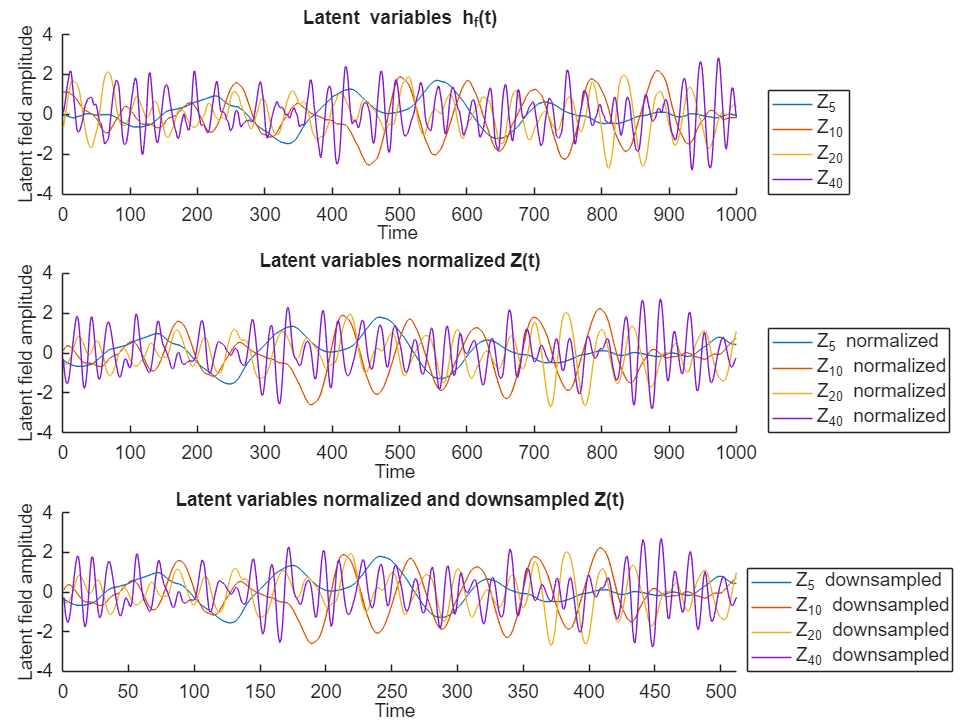

figure('Position',[50 50 1000 750])
tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
h_f_colors = lines(param.N_F);

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_pt(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d}', param.f_peak(f))]);
end
xlabel('Time ')
ylabel('Latent field amplitude')
title('Latent variables h_f(t)')
xlim([0 1000]);
ylim([-4 4]);
legend( 'Show', 'Location', 'southeastoutside');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_normalized(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d} normalized', param.f_peak(f))]);
end
xlabel('Time  ')
ylabel('Latent field amplitude')
title('Latent variables normalized Z(t)')
xlim([0 1000]);
ylim([-4 4]);
legend( 'Show','Location', 'southeastoutside');
hold off;

nexttile
hold on;
for f=1:param.N_F
    plot(h_f_normalized_ds(:, f), 'Color', h_f_colors(f, :),'DisplayName', [sprintf('Z_{%d} downsampled', param.f_peak(f))]);
end
xlabel('Time  ')
ylabel('Latent field amplitude')
title('Latent variables normalized and downsampled Z(t)')
xlim([0 1000*fs_new/fs_orig]);
ylim([-4 4]);
legend( 'Show','Location', 'southeastoutside');
hold off;

set(findall(gcf,'-property','FontSize'),'FontSize',14);

% % Trying different learning rates
% learning_rates = [0.1, 0.01, 0.001, 1e-4, 1e-5, 1e-7, 1e-10];
% hiddenSize = [16, 8, 4];
% numLatents = 4; 
% for lr = learning_rates
%     run_autoencoder(s_eeg_ds_small,s_eeg_test_ds,numLatents, ...
%         h_f_normalized_ds, h_f_normalized_test_ds, ... 
%         hiddenSize, 1000, lr);
% end

- **Learning rate 1e-3 looks better for Latent 4 and others. Suprisingly they don't change as much. **

% 1) Prepare data
X_train = s_eeg_ds;       % [Nchan × T]
X_test  = s_eeg_test_ds;  % [Nchan × Ttest]

% 1.1) Using a smaller subset
% Use only 10-20% of your data for training
subset_size = round(0.1 * size(X_train, 2));
X_train_small = X_train(:, 1:subset_size);

% 2) Define net
hiddenSize =  4;     % e.g. 4
% hiddenSize = [16, 8, 4];     % e.g. 4
% hiddenSize = [64, 32];

net = feedforwardnet(hiddenSize, 'trainrp'); % trainscg, trainlm , traingdx, trainrp (better), 

% net.divideFcn = 'dividetrain';
net.performFcn = 'mse';
net.performParam.regularization = 0;
net.layers{1}.transferFcn = 'logsig';
net.layers{end}.transferFcn = 'purelin'; % 'purelin'
net.trainParam.epochs = 200; % ofter overfiting 
net.trainParam.lr     = 1e-3; % try 0.01, 1e-3
net.trainParam.showWindow = true; % false
net.trainParam.max_fail = 1000; % validation based stopping, default is 6
net.trainParam.min_grad = 0; % disabiling small-graident stopping

% Turn off internal normalization
net.inputs{1}.processFcns = {};
net.outputs{2}.processFcns = {};
% X_train = (X_train - mean(X_train, 2)) ./ std(X_train, 0, 2);
% h_f_processed = normalize(h_f_processed);


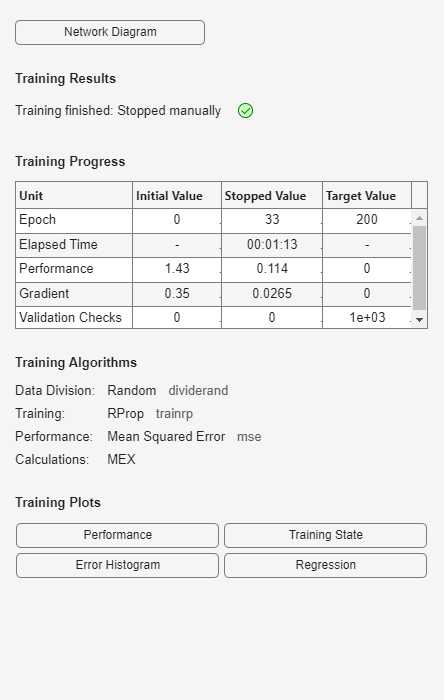

% 3) Train
[net, tr] = train(net, X_train_small, X_train_small,'useGPU','yes');

% 4) Compute encoder outputs manually
W_enc = net.IW{1,1};
b_enc = net.b{1};

Z_train_c = logsig(W_enc * X_train_small + b_enc)';  % [T × hiddenSize]
Z_test_c  = logsig(W_enc * X_test  + b_enc)';  % [Ttest × hiddenSize]

% Train set:
% a1_train = logsig(net.IW{1,1} * X_train + net.b{1});               % 8 neurons
% Z_train_c = logsig(net.LW{2,1} * a1_train + net.b{2})';            % 4 neurons → [T x 4]
% 
% % Test set:
% a1_test = logsig(net.IW{1,1} * X_test + net.b{1});
% Z_test_c = logsig(net.LW{2,1} * a1_test + net.b{2})';              % [Ttest x 4]

% % === Train set ===
% a1_train = logsig(net.IW{1,1} * X_train + net.b{1});         % Layer 1
% a2_train = logsig(net.LW{2,1} * a1_train + net.b{2});        % Layer 2
% Z_train_c = logsig(net.LW{3,2} * a2_train + net.b{3})';      % Layer 3 (T x 4)
% 
% % === Test set ===
% a1_test = logsig(net.IW{1,1} * X_test + net.b{1});
% a2_test = logsig(net.LW{2,1} * a1_test + net.b{2});
% Z_test_c = logsig(net.LW{3,2} * a2_test + net.b{3})';        % (Ttest x 4)


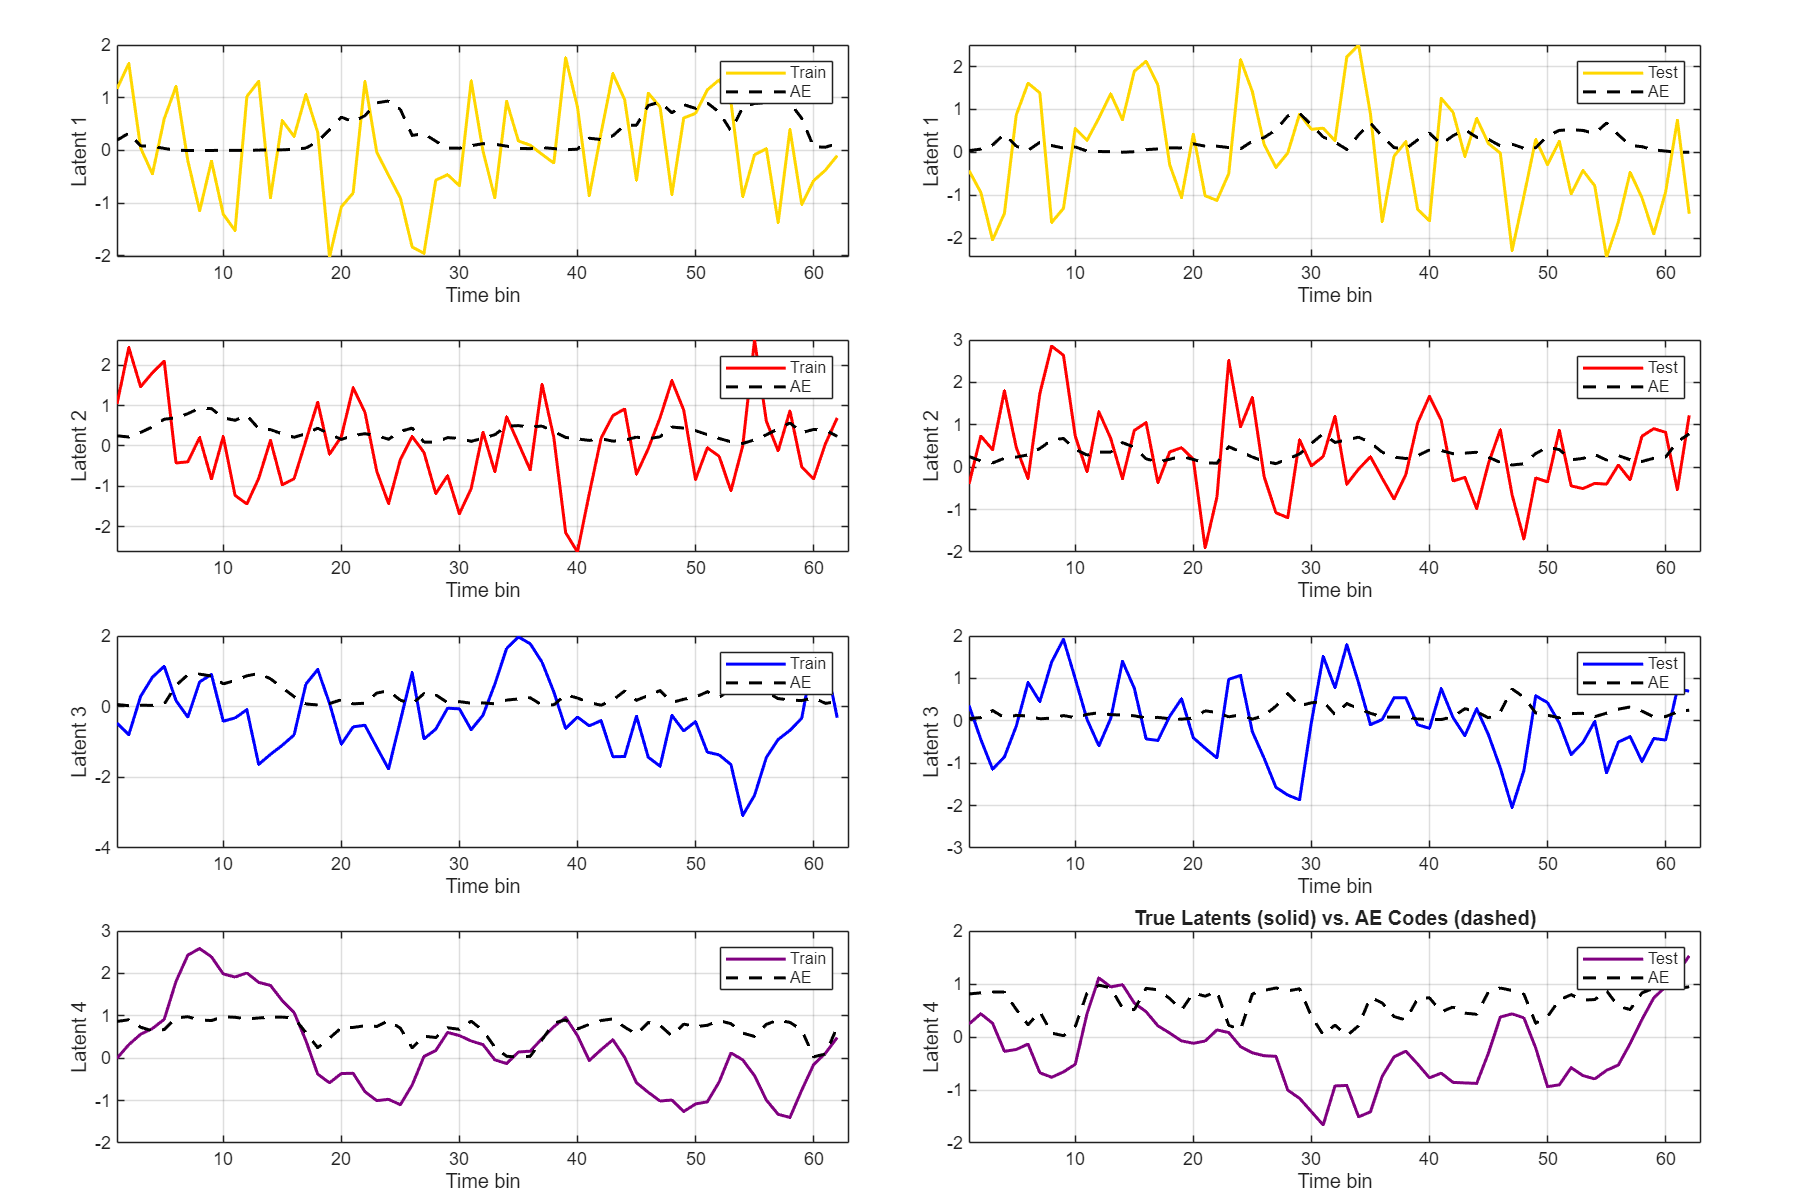

% 5) Plot the train and test 
% Define the colors: yellow, red, blue, purple
cols = [
    1.0, 0.8431, 0.0;   % gold
    1.0, 0.0, 0.0;   % red
    0.0, 0.0, 1.0;   % blue
    0.5, 0.0, 0.5    % purple
];

% Prepare figure
figure('Name','True vs. AE Latents (Overlayed Subplots)', 'Position', [100, 100, 1200, 800]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for f = 1:param.N_F
    nexttile;
    t_l = size(Z_train_c,1);

    % plot(1:T_new, h_f_processed(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    % plot(1:T_new, Z_train_c(:,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    plot(1:t_l, h_f_normalized_ds(1:t_l,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(1:t_l, Z_train_c(1:t_l,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    ylabel(sprintf('Latent %d', f));
    xlabel('Time bin');
    xlim([1 t_l+1]);
    legend({'Train', 'AE'});
    grid on;
    hold off;

    nexttile;
    plot(1:t_l, h_f_normalized_test_ds(1:t_l,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(1:t_l, Z_test_c(1:t_l,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    ylabel(sprintf('Latent %d', f));
    xlabel('Time bin');
    xlim([1 t_l+1]);
    legend({'Test', 'AE'});
    grid on;
    hold off;
end
    %set(gca, 'XTickLabel', []);
title('True Latents (solid) vs. AE Codes (dashed)');

% 7) Now compute your reconstruction‐MSE exactly as before:
numLatents = size(Z_train_c,2);
% reconErr = zeros(numLatents,1);
% reconErrTest = zeros(numLatents,1);
% for f = 1:numLatents
%   % you'd regress h_f_processed(:,f) on Z_train(:,1:f) etc.
%   % w = lsqlin(Z_train_c,    h_f_processed(:,f));
%   w = lsqlin(Z_train_c,    h_f_processed(1:t_l,f));
%   w_test = lsqlin(Z_test_c, h_f_processed_test(:,f));
%   reconErr(f)     = mean((h_f_processed(1:t_l,f)     - Z_train_c*w    ).^2);
%   reconErrTest(f) = mean((h_f_processed_test(:,f) - Z_test_c*w_test).^2);
% end
% 6) Compute encoder outputs (simplified)
encoded_train = net(X_train_small);  % Use network's built-in encoding
encoded_test  = net(X_test);         % Same for test data

% 6.1) Reconstruction MSE calculation (updated)
% Option A: If you want to keep original 4 latents (h_f_processed)
% 1) First verify all dimensions
fprintf('Encoded train: %dx%d | h_f_processed: %dx%d\n', ...
    size(encoded_train), size(h_f_normalized_ds));

Encoded train: 32x62 | h_f_processed: 615x4


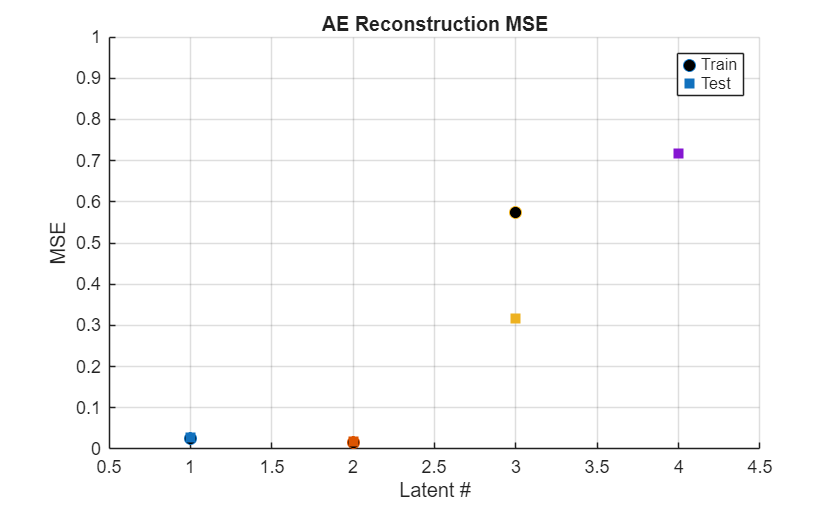


% 2) Transpose h_f_processed to match standard AE conventions
h_f_train = h_f_normalized_ds(1:subset_size,:)';  % [4 × subset_size]
h_f_test = h_f_normalized_test_ds';               % [4 × Ttest]

% 3) Project latent space -> original variables
proj_matrix = encoded_train / h_f_train;  % [32 × 4] matrix
% Equivalent to: proj_matrix = lsqlin(h_f_train', encoded_train')';

% 4) Reconstruct using projection
recon_train = proj_matrix' * encoded_train;  % [4 × subset_size]
recon_test = proj_matrix' * encoded_test;    % [4 × Ttest]

% 5) Compute MSE
reconErr = mean((recon_train - h_f_train).^2, 2);      % [4 × 1]
reconErrTest = mean((recon_test - h_f_test).^2, 2);    % [4 × 1]

% 8) Plot
figure; hold on;
c = lines(4);
for f=1:4
  plot(f, reconErr(f)/100,     'o','Color',c(f,:),'MarkerFaceColor','k');
  plot(f, reconErrTest(f)/100,'s','Color',c(f,:),'MarkerFaceColor',c(f,:));
end
xlim([0.5 4+0.5]);
ylim([0 1]);
legend('Train','Test');
xlabel('Latent #'); ylabel('MSE');
title('AE Reconstruction MSE');
grid on;


% 8) Plot - Updated for 4 latent variables
% figure; 
% hold on;
% set(gcf, 'Position', [100 100 800 400]); % Larger figure size
% 
% % Use consistent colors for the 4 latents
% c = lines(4); % Now fixed to 4 colors regardless of autoencoder's latent size
% 
% % Plot train vs test MSE for each true latent
% for f = 1:4
%     h_train = plot(f, reconErr(f), 'o', 'Color', c(f,:), ...
%                   'MarkerSize', 10, 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
%     h_test = plot(f, reconErrTest(f), 's', 'Color', c(f,:), ...
%                   'MarkerSize', 10, 'MarkerFaceColor', c(f,:), 'LineWidth', 1.5);
% end
% 
% % Formatting
% xlim([0.5 4.5]);
% xticks(1:4);
% xticklabels({'Latent 1', 'Latent 2', 'Latent 3', 'Latent 4'});
% 
% % Dynamic Y-axis scaling
% % max_mse = max([reconErr; reconErrTest]) * 1.1;
% % ylim([0 max_mse]);
% ylim([0 100]);
% % Labels and legend
% legend([h_train h_test], {'Train MSE', 'Test MSE'}, 'Location', 'northeast');
% xlabel('Latent Variable');
% ylabel('Reconstruction MSE');
% title(sprintf('Autoencoder Performance\n(Projected from %dD to 4D Latents)', size(encoded_train,1)));
% 
% % Grid and appearance
% grid on;
% set(gca, 'FontSize', 12, 'Box', 'on');
% 
% % Optional: Add value labels
% for f = 1:4
%     text(f, reconErr(f)+0.05*max_mse, sprintf('%.3f', reconErr(f)), ...
%         'HorizontalAlignment', 'center', 'FontSize', 10);
%     text(f, reconErrTest(f)-0.05*max_mse, sprintf('%.3f', reconErrTest(f)), ...
%         'HorizontalAlignment', 'center', 'FontSize', 10);
% end

for f = 1:param.N_F
    corr_val = corr( h_f_train(f,:)',h_f_test(f,1:subset_size)');
    fprintf('Latent %d correlation: %.2f\n', f, corr_val);
end

Latent 1 correlation: 0.05
Latent 2 correlation: -0.29
Latent 3 correlation: 0.21
Latent 4 correlation: 0.06


function [X_windows] = make_windows(X, winLen, hop)
% X: channels x time
% returns: windows as [nWindows x (channels*winLen)] rows for trainNetwork
[nCh, T] = size(X);
nWins = floor((T - winLen)/hop) + 1;
X_windows = zeros(nWins, nCh*winLen);
for w = 1:nWins
    idx = (w-1)*hop + (1:winLen);
    patch = X(:, idx);           % channels x winLen
    X_windows(w, :) = patch(:)'; % flatten (row)
end
end


X = s_eeg_like;

batch_size = 80; %fs_orig
% batch_size = 256;
T = size(X,2);
idx_split = floor(0.8*T);
X_train = X(:,1:idx_split);
X_test  = X(:,idx_split+1:end);

fs = fs_orig;                  % e.g. 512
winLen = round(1 * fs);       % 1 second windows
hop = round(winLen/2);        % 50% overlap
Xtr_w = make_windows(X_train, winLen, hop);   % rows = windows
Xte_w = make_windows(X_test,  winLen, hop);
% Now train with inputDim = nCh*winLen (modify network input accordingly)


Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         5.07 |         6.09 |      12.8519 |      18.5168 |          0.0010 |
|       1 |          50 |       00:00:04 |         4.41 |              |       9.7385 |              |          0.0010 |
|       1 |         100 |       00:00:05 |         4.31 |              |       9.2897 |              |          0.0010 |
|       1 |         150 |       00:00:05 |         3.38 |              |       5.7103 |              |          0.0010 |
|       

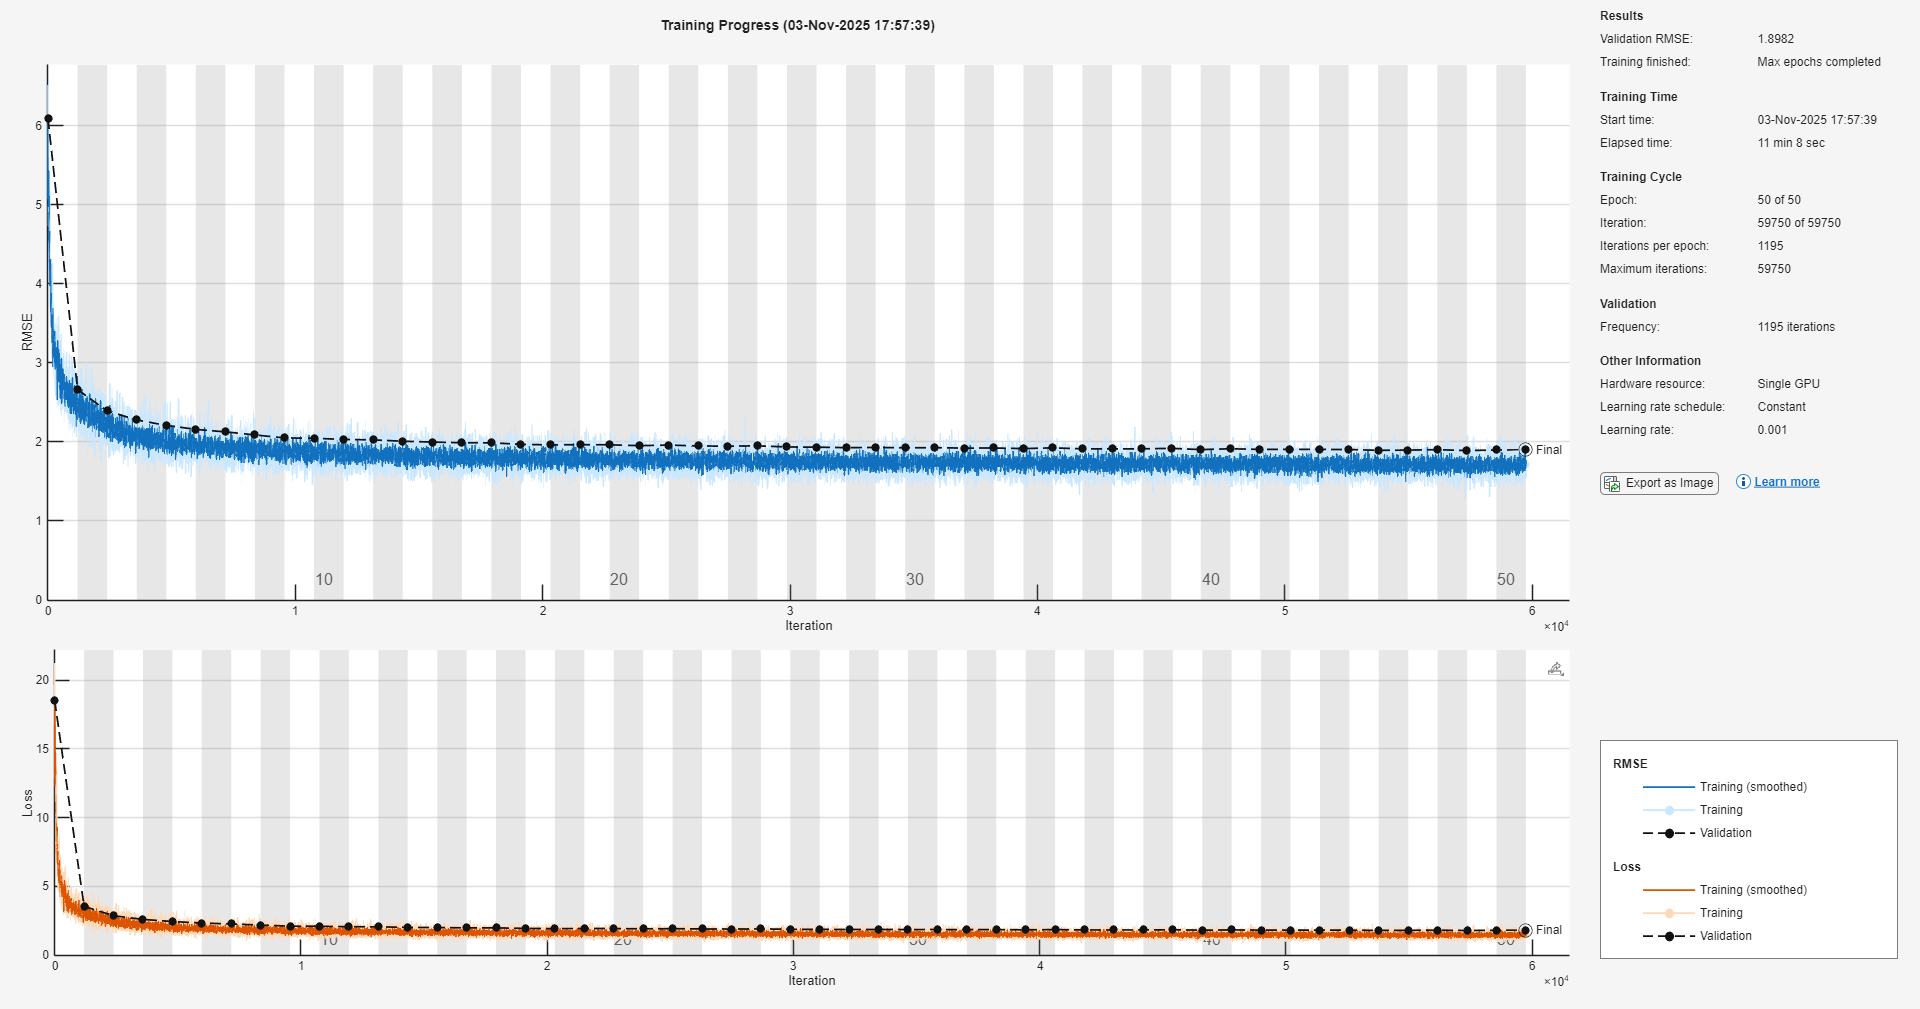

[net, info] = trainEEGAutoencoder(X_train, X_test,  ...
    'encoderLayerSizes', [64,32], ...
    'bottleneckSize', 4, ...
    'decoderLayerSizes', [32,64], ...
    'encoderActivations', {'relu','relu'}, ...
    'decoderActivations', {'relu','relu'}, ...
    'outputActivation', "none", ...
    'epochs', 50, ...
    'batchSize', batch_size, ...
    'learnRate', 1e-3);

% Encode into latent space
Z_train_c = activations(net, X_train.', 'bottleneck', 'OutputAs','rows');
Z_test_c  = activations(net, X_test.',  'bottleneck', 'OutputAs','rows');

function Xrec_full = overlap_add(Xrec_windows, h_f, winLen, hop_size)
    % overlap_add: reconstruct multichannel signal from overlapping windows
    %
    % Inputs:
    %   Xrec_windows - [nWindows × (nCh * winLen)] reconstructed segments
    %   h_f          - filter kernel (optional, or [] if none)
    %   winLen       - samples per window
    %   hop_size     - overlap step (default: winLen/2)
    %
    % Output:
    %   Xrec_full - reconstructed [nCh × totalTime] signal

    if nargin < 4
        hop_size = winLen / 2;
    end

    nWins = size(Xrec_windows, 1);
    nCh = size(Xrec_windows, 2) / winLen;
    total_len = (nWins - 1) * hop_size + winLen;
    Xrec_full = zeros(nCh, total_len);

    % Go through each window
    for w = 1:nWins
        % Reshape flat window into [nCh × winLen]
        start_idx = (w - 1) * hop_size + 1;
        win = reshape(Xrec_windows(w,:), [nCh, winLen]);

        % If a filter kernel is provided, convolve each channel
        if ~isempty(h_f)
            for ch = 1:nCh
                conv_res = conv(win(ch,:), h_f(:,min(ch, size(h_f,2))));
                end_idx = start_idx + length(conv_res) - 1;
                Xrec_full(ch, start_idx:end_idx) = Xrec_full(ch, start_idx:end_idx) + conv_res;
            end
        else
            end_idx = start_idx + winLen - 1;
            Xrec_full(:, start_idx:end_idx) = Xrec_full(:, start_idx:end_idx) + win;
        end
    end

    % Normalize overlap regions (to prevent amplitude doubling)
    overlap_count = zeros(1, total_len);
    for w = 1:nWins
        start_idx = (w - 1) * hop_size + 1;
        end_idx = start_idx + winLen - 1;
        overlap_count(start_idx:end_idx) = overlap_count(start_idx:end_idx) + 1;
    end
    Xrec_full = Xrec_full ./ max(overlap_count, 1);
end


% Reconstruct from autoencoder directly
Xrec_train = predict(net, X_train.');
Xrec_test  = predict(net, X_test.');

% Reshape reconstructed windows back to [channels × time]
nCh = size(X_train, 1);
Xrec_train_full = overlap_add(Xrec_train, h_f_normalized(1:idx_split,:), winLen);

Error using zeros
Size inputs must be integers.
Error in DLV_dimensionality_reduction_methods>overlap_add (line 1481)
    Xrec_full = zeros(nCh, total_len);
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

Xrec_test_full  = overlap_add(Xrec_test,  h_f_normalized(idx_split+1:end, :), winLen);



% 7) Now compute your reconstruction‐MSE exactly as before:
% numLatents = size(Z_train_c,2);
% reconErr = zeros(numLatents,1);
% reconErrTest = zeros(numLatents,1);
% for f = 1:numLatents
%   % you'd regress h_f_processed(:,f) on Z_train(:,1:f) etc.
%   % w = lsqlin(Z_train_c,    h_f_processed(:,f));
%   w = lsqlin(Z_train_c,    h_f_processed(1:t_l,f));
%   w_test = lsqlin(Z_test_c, h_f_processed_test(:,f));
%   reconErr(f)     = mean((h_f_processed(1:t_l,f)     - Z_train_c*w    ).^2);
%   reconErrTest(f) = mean((h_f_processed_test(:,f) - Z_test_c*w_test).^2);
% end
% 6) Compute encoder outputs (simplified)
% encoded_train = net(X_train);  % Use network's built-in encoding
% encoded_test  = net(X_test);         % Same for test data
% 
% % 6.1) Reconstruction MSE calculation (updated)
% % Option A: If you want to keep original 4 latents (h_f_processed)
% % 1) First verify all dimensions
% fprintf('Encoded train: %dx%d | h_f_processed: %dx%d\n', ...
%     size(encoded_train), size(h_f_normalized_ds));
% 
% % 2) Transpose h_f_processed to match standard AE conventions
% h_f_train = h_f_normalized_ds(1:subset_size,:)';  % [4 × subset_size]
% h_f_test = h_f_normalized_test_ds';               % [4 × Ttest]
% 
% % 3) Project latent space -> original variables
% proj_matrix = encoded_train / h_f_train;  % [32 × 4] matrix
% % Equivalent to: proj_matrix = lsqlin(h_f_train', encoded_train')';
% 
% % 4) Reconstruct using projection
% recon_train = proj_matrix' * encoded_train;  % [4 × subset_size]
% recon_test = proj_matrix' * encoded_test;    % [4 × Ttest]
% 
% % 5) Compute MSE
% reconErr = mean((recon_train - h_f_train).^2, 2);      % [4 × 1]
% reconErrTest = mean((recon_test - h_f_test).^2, 2);    % [4 × 1]
% 
% % 8) Plot
% figure; hold on;
% c = lines(4);
% for f=1:4
%   plot(f, reconErr(f)/100,     'o','Color',c(f,:),'MarkerFaceColor','k');
%   plot(f, reconErrTest(f)/100,'s','Color',c(f,:),'MarkerFaceColor',c(f,:));
% end
% xlim([0.5 4+0.5]);
% ylim([0 1]);
% legend('Train','Test');
% xlabel('Latent #'); ylabel('MSE');
% title('AE Reconstruction MSE');
% grid on;

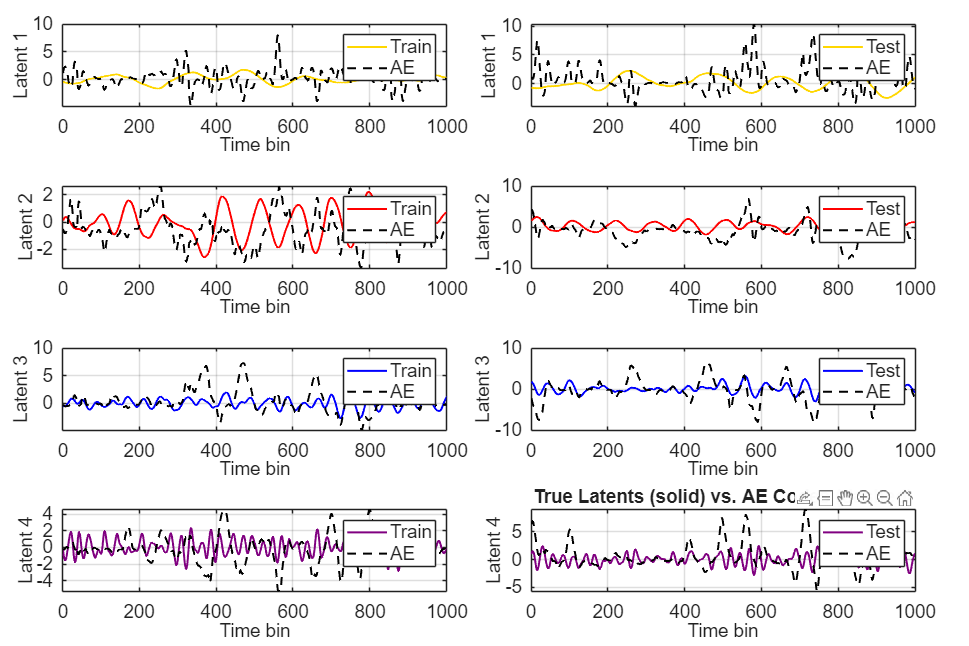

% % 4) Compute encoder outputs manually
% W_enc = net.IW{1,1};
% b_enc = net.b{1};
% 
% Z_train_c = logsig(W_enc * X_train_small + b_enc)';  % [T × hiddenSize]
% Z_test_c  = logsig(W_enc * X_test  + b_enc)';  % [Ttest × hiddenSize]

% 5) Plot the train and test 
% Define the colors: yellow, red, blue, purple
cols = [
    1.0, 0.8431, 0.0;   % gold
    1.0, 0.0, 0.0;   % red
    0.0, 0.0, 1.0;   % blue
    0.5, 0.0, 0.5    % purple
];

% Prepare figure
figure('Name','True vs. AE Latents (Overlayed Subplots)', 'Position', [100, 100, 1200, 800]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for f = 1:param.N_F
    nexttile;
    t_l = length(h_f_normalized(idx_split+1:end,1));

    % plot(1:T_new, h_f_processed(:,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    % plot(1:T_new, Z_train_c(:,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    plot(1:idx_split, h_f_normalized(1:idx_split,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(1:idx_split, Z_train_c(1:idx_split,f), '--', 'Color', 'k', 'LineWidth', 1.5);
    ylabel(sprintf('Latent %d', f));
    xlabel('Time bin');
    xlim([0 1000]);
    legend({'Train', 'AE'});
    grid on;
    hold off;

    nexttile;
    plot(1:t_l, h_f_normalized(idx_split+1:end,f), '-',  'Color', cols(f,:), 'LineWidth', 1.5); hold on;
    plot(1:t_l, Z_test_c(1:t_l,f),      '--', 'Color', 'k', 'LineWidth', 1.5);
    ylabel(sprintf('Latent %d', f));
    xlabel('Time bin');
    xlim([0 1000]);
    legend({'Test', 'AE'});
    grid on;
    hold off;
end
    %set(gca, 'XTickLabel', []);
title('True Latents (solid) vs. AE Codes (dashed)');
set(findall(gcf,'-property','FontSize'),'FontSize',14);

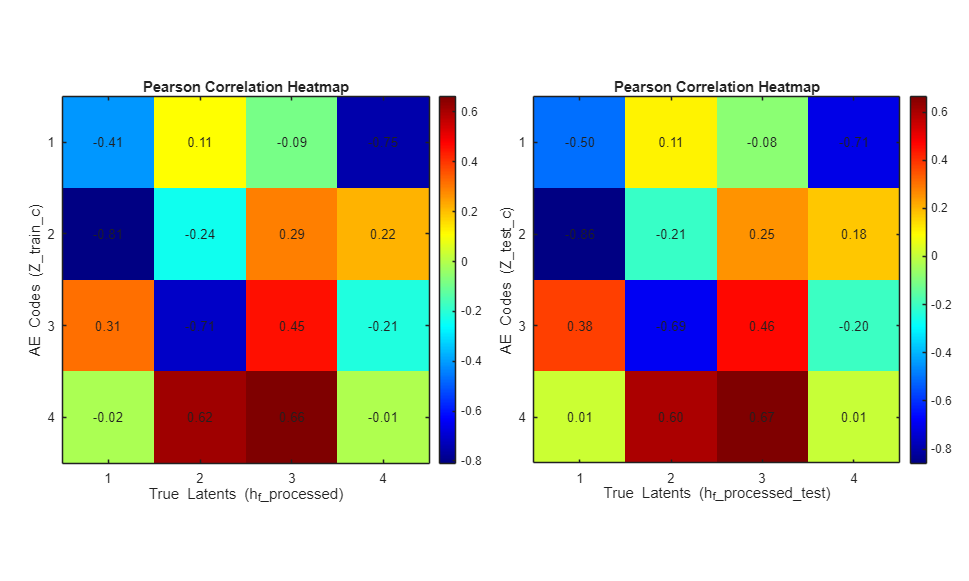

% Assume:
% - Z_train_c is [T x numLatents]
% - h_f_processed is [T x numLatents]
numLatents = size(Z_train_c, 2);
corr_matrix = zeros(numLatents);
corr_matrix_test = zeros(numLatents);

for i = 1:numLatents
    for j = 1:numLatents
        c = corrcoef(Z_train_c(:,i), h_f_normalized(1:idx_split,j));
        corr_matrix(i,j) = c(1,2);

        c_test = corrcoef(Z_test_c(:,i), h_f_normalized(idx_split+1:end,j));
        corr_matrix_test(i,j) = c_test(1,2);
    end
end

% Plot correlation matrix
figure('Name','Correlation between AE Codes and True Latents', 'Position', [100, 100, 1000, 600]);
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile;
imagesc(corr_matrix);
colorbar;
colormap('jet');
axis square;

xticks(1:numLatents);
yticks(1:numLatents);
xlabel('True Latents (h_f\_processed)');
ylabel('AE Codes (Z\_train\_c)');
title('Pearson Correlation Heatmap');

% Optional: Annotate values
textStrings = num2str(corr_matrix(:), '%.2f');
textStrings = strtrim(cellstr(textStrings));
[x, y] = meshgrid(1:numLatents);
hStrings = text(x(:), y(:), textStrings(:), 'HorizontalAlignment', 'center');

nexttile;
imagesc(corr_matrix_test);
colorbar;
colormap('jet');
axis square;

xticks(1:numLatents);
yticks(1:numLatents);
xlabel('True Latents (h_f\_processed\_test)');
ylabel('AE Codes (Z\_test\_c)');
title('Pearson Correlation Heatmap');

% Optional: Annotate values
textStrings_test = num2str(corr_matrix_test(:), '%.2f');
textStrings_test = strtrim(cellstr(textStrings_test));
[x, y] = meshgrid(1:numLatents);
hStrings_test = text(x(:), y(:), textStrings_test(:), 'HorizontalAlignment', 'center');

- Correlation values near 0 are weak or no relationship, while the ones close to -1 or 1 are strong correlation.

- For training: True latent 1 correlates negatively with 3, true latent 2 correlates negatively with 3, true latenet 3 also correlates negatively with 3, and true latent 4 correlates negatively with latent 3.

- For testing: True latent 1 correlates positively with latenet 4, true latent 2 corrolates positively with latenet 1, true latent 3 negatively with latenet 3, and true latent 4 correlates negatively with latent 2. 

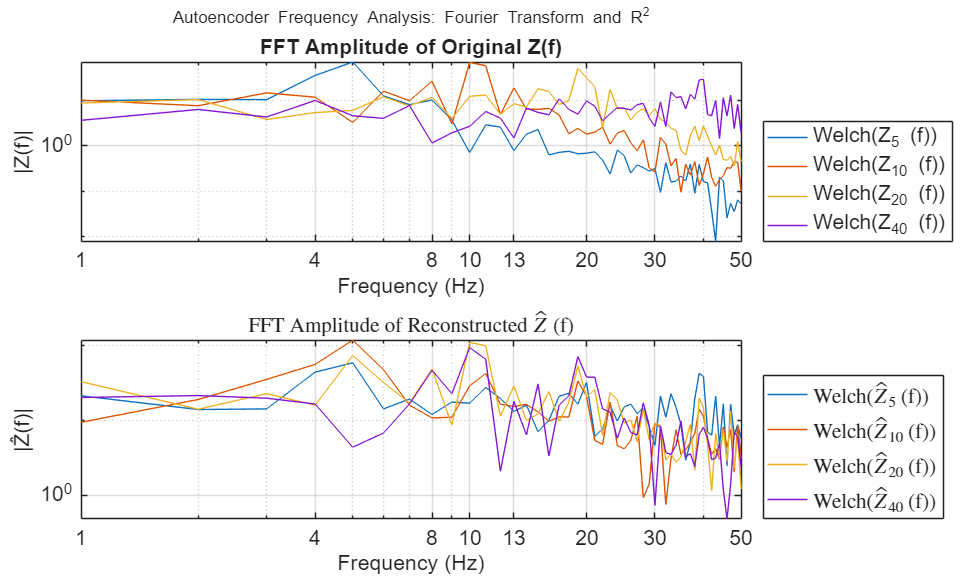

% band-wise spectra R^2 and coherence
N = size(Z_train_c, 1);
trial_dur = 1;                 % seconds per "trial"
L         = trial_dur * fs_orig;    % samples per trial
nTrials   = floor(N/L);

fs = fs_orig;  % or whatever your sample rate is
f = (0:L-1)*(fs_orig/L);    % frequency vector for each trial

% Compute R^2(f)
R2_trials_ae = zeros(L, param.N_F, nTrials);
Ht_ae = zeros(L, param.N_F, nTrials);
Hr_ae = zeros(L, param.N_F, nTrials);
Z_true_trials   = zeros(L, nTrials, param.N_F);
Z_recon_ae_trials  = zeros(L, nTrials, param.N_F);


for tr = 1:nTrials
    idx = (tr-1)*L + (1:L);        % sample indices for this trial
  
    % extract one trial
    Z_true_trials(:,tr,:)  = h_f_normalized(idx,:);      
    Z_recon_ae_trials(:,tr,:) = Z_train_c(idx,:);
    
    % FFT each latent dim
    Ht_ae(:,:,tr) = fft(Z_true_trials(:,tr,:));     % size [L×N_F]
    Hr_ae(:,:,tr) = fft(Z_recon_ae_trials(:,tr,:));
    
    % compute trial‐wise R^2(f) for each dimension
    for fidx = 1:param.N_F
        num = abs(Ht_ae(:,fidx,tr) - Hr_ae(:,fidx,tr)).^2;
        den = abs(Ht_ae(:,fidx,tr)).^2 + eps;   % avoid zero‐divide
        R2_trials_ae(:,fidx,tr) = 1 - num./den;
    end
end

% Now average across trials
R2_avg_ae = mean(R2_trials_ae, 3);   % [L×N_F]
Ht_avg_ae = mean(Ht_ae, 3);
Hr_avg_ae = mean(Hr_ae, 3);

nHz = L/2+1;
f_plot = f(1:nHz);

bands = struct( ...
    'delta', [1 4], ...
    'theta', [4 8], ...
    'alpha', [8 13], ...
    'beta',  [13 30], ...
    'gamma', [30 50] ...
);
band_names = fieldnames(bands);
nBands = numel(band_names);

band_avg_R2_ae = zeros(nBands, param.N_F);  % rows: bands, cols: latent fields

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);  % [f_low f_high]
    
    % Get indices within this band
    idx = f >= f_range(1) & f <= f_range(2);
    
    for fidx = 1:param.N_F
        band_avg_R2_ae(b, fidx) = mean(R2_avg_ae(idx, fidx));
    end
end

h_f_colors = lines(param.N_F);
figure('Position',[50 50 1000 600])
tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('Autoencoder Frequency Analysis: Fourier Transform and R^2');

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Ht_avg_ae(idx,fidx)),'Color',h_f_colors(fidx,:),'DisplayName',['Welch(Z_{' num2str(param.f_peak(fidx)) '} (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Z(f)|')
title('FFT Amplitude of Original Z(f)')
xlim([1, 50]);
xticks([1, 4, 8, 10, 13, 20, 30, 50]); % Example major ticks
% ylim([0.01, 100]);
% yticks([0.1, 1, 10, 100]);
legend('show','Location','southeastoutside');
grid on;
hold off;

nexttile
for fidx=1:param.N_F
    idx = 1:L/2+1;
    loglog(f_plot(idx), abs(Hr_avg_ae(idx,fidx)), 'Color',h_f_colors(fidx,:),'DisplayName',['Welch($\hat{Z}_{' num2str(param.f_peak(fidx)) '}$ (f))']); % 
    hold on;
end
xlabel('Frequency (Hz)')
ylabel('|Ẑ(f)|')
title('FFT Amplitude of Reconstructed $\hat{Z}$ (f)', 'Interpreter', 'latex')
xlim([1, 50])
% Set major tick values
xticks([1, 4, 8, 10, 13, 20, 30, 50]) % Example major ticks
% ylim([0.1, 100]);
% yticks([0.01, 1, 10, 100]);
legend('show', 'Interpreter', 'latex','Location','southeastoutside');
grid on;

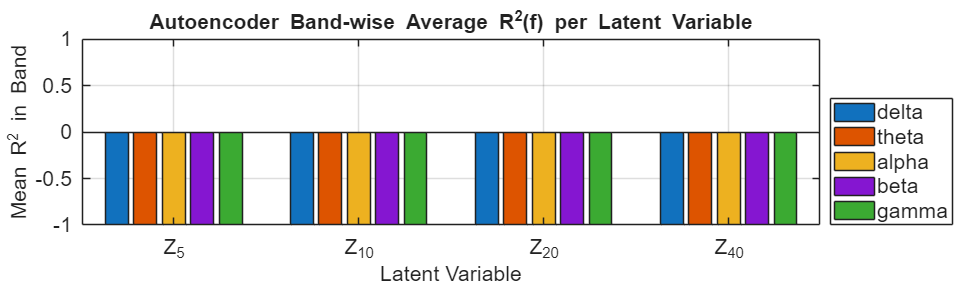

hold off;
set(findall(gcf,'-property','FontSize'),'FontSize',16);

figure('Position',[50 50 1000 300])
tiledlayout(1, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
bar(band_avg_R2_ae');
set(gca, 'XTickLabel', arrayfun(@(i) sprintf('Z_{%d}',param.f_peak(i)), 1:i, 'UniformOutput', false));
ylim([-1 1]);
legend(band_names, 'Location', 'southeastoutside');
ylabel('Mean R^2 in Band');
xlabel('Latent Variable');
title('Autoencoder Band-wise Average R^2(f) per Latent Variable');

grid on;
set(findall(gcf,'-property','FontSize'),'FontSize',16);

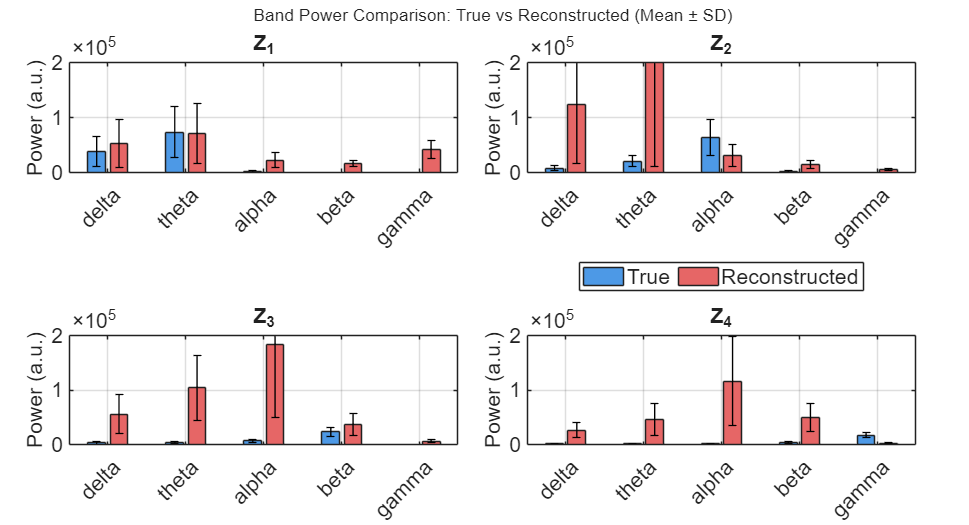

% Trial band power for true and reconstructed latent variables
% --- Compute trial-averaged band power for true and reconstructed ---
band_power_true = zeros(nBands, size(h_f_normalized_ds,2));
band_power_recon = zeros(nBands, size(h_f_normalized_ds,2));
band_power_true_std = zeros(nBands, size(h_f_normalized_ds,2));
band_power_recon_std = zeros(nBands, size(h_f_normalized_ds,2));

for b = 1:nBands
    band = band_names{b};
    f_range = bands.(band);
    idx = f >= f_range(1) & f <= f_range(2);

    for fidx = 1:size(h_f_normalized_ds,2)
        % Compute trial-wise power (mean across band frequencies)
        trial_power_true = mean(abs(Ht_ae(idx,fidx,:)).^2, 1, 'omitnan');
        trial_power_recon = mean(abs(Hr_ae(idx,fidx,:)).^2, 1, 'omitnan');

        % Average across trials
        band_power_true(b,fidx) = mean(trial_power_true(:));
        band_power_recon(b,fidx) = mean(trial_power_recon(:));

        % Std across trials
        band_power_true_std(b,fidx) = std(trial_power_true(:));
        band_power_recon_std(b,fidx) = std(trial_power_recon(:));
    end
end

% --- Add new figure section for bar chart ---
figure('Position',[100 100 1200 650])
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
sgtitle('Band Power Comparison: True vs Reconstructed (Mean ± SD)');

for fidx = 1:size(h_f_normalized_ds,2)
    nexttile
    % prepare data for grouped bars: [true; recon]
    bar_data = [band_power_true(:,fidx), band_power_recon(:,fidx)];
    bar_std = [band_power_true_std(:,fidx), band_power_recon_std(:,fidx)];
    bh = bar(bar_data); hold on

    % Add error bars
    ngroups = size(bar_data,1);
    nbars = size(bar_data,2);
    groupwidth = min(0.8, nbars/(nbars + 1.5));
    for i = 1:nbars
        % Calculate center of each bar
        x = (1:ngroups) - groupwidth/2 + (2*i-1) * groupwidth / (2*nbars);
        errorbar(x, bar_data(:,i), bar_std(:,i), 'k', 'linestyle', 'none', 'LineWidth', 1);
    end

    % Style
    bh(1).FaceColor = [0.3 0.6 0.9]; % true
    bh(2).FaceColor = [0.9 0.4 0.4]; % recon
    ylim([0 2e5]);
    ylabel('Power (a.u.)')
    set(gca, 'XTickLabel', band_names, 'XTickLabelRotation', 45)
    title(['Z_' num2str(fidx)])
    
    grid on
end

legend({'True','Reconstructed'}, 'Location','northoutside','Orientation','horizontal')
set(findall(gcf,'-property','FontSize'),'FontSize',16);

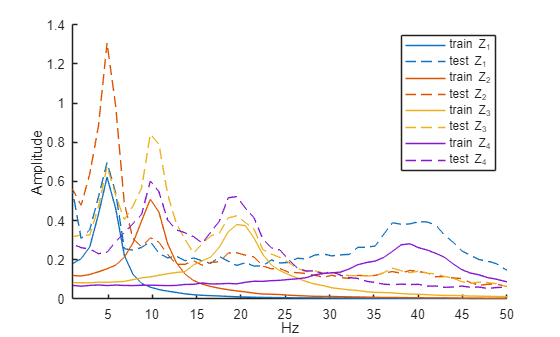

% single latent channel PSD

[Px, f_pw] = pwelch(h_f_normalized, round(fs*1), round(fs*0.5), [], fs);
[Phat, f_pw_test] = pwelch(Z_test_c, round(fs*1), round(fs*0.5), [], fs);

figure; 
hold on;
for fidx=1:size(h_f_normalized,2)
    loglog(f_pw, sqrt(Px(:,fidx)), 'Color',h_f_colors(fidx,:), 'DisplayName', ['train Z_' num2str(fidx)]);
    loglog(f_pw_test, sqrt(Phat(:,fidx)), '--','Color',h_f_colors(fidx,:), 'DisplayName', ['test Z_' num2str(fidx)]);
    legend('show');
end
xlim([1 50]); 

xlabel('Hz'); ylabel('Amplitude');
hold off;

Error using signal.internal.spectral.welchparse (line 82)
The number of rows of the two inputs must be equal to calculate the cross spectral density.
Error in welch (line 57)
    signal.internal.spectral.welchparse(x,funcName,varargin{1:max(0,estIdx-1)},varargin{estIdx+1:end});
    ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^


[Cxy, fcoh] = mscohere(h_f_normalized, Z_train_c, round(fs*1), round(fs*0.5), [], fs);
figure; plot(fcoh, Cxy); xlim([1 50]); xlabel('Hz'); ylabel('Coherence');

for k=1:param.N_F
    r = corr(h_f_true(:,k), h_f_recon(:,k));
    mse = mean((h_f_true(:,k)-h_f_recon(:,k)).^2);
    fprintf('Latent %d: corr=%.3f MSE=%.3f\n', k, r, mse);
end


#### Custom Variational Autoencoder with more knobs to overfit/underfit/balance the training